# Ray-tracing Based Mobile Wireless Channel Simulator 

## Mobile Scenario Example - NU campus LTE small cell and WIFI coexistence 

### Scenario configuration

This simulator supports custom mobility pattern

% Parameters Configuration
parameters.origin = [42.34025, -71.08848];              %Wireless environment origin
parameters.osmfile = "NUcampus.osm";                    %Wireless environment 3D Model OSM file
parameters.fc = 5.8e9;                                  %LTE ISM band Center freq. (Hz)
parameters.nodes.names = {'LTE' 'WIFI' 'UE#1' 'UE#2' 'WIFIUE'};  %Nodes names
parameters.nodes.powers = {30, 22, 20, 20, 15};         %Transmit power (dBm)
parameters.nodes.coordinates = {[42.3405645965253,-71.0892925339939],...        %stationary nodes coordinates
                                [42.3398095978303,-71.0884277156665],...
                                [42.341482,-71.086650; 42.341102,-71.087238; 42.339903,-71.090416],...
                                [42.339757,-71.090343; 42.341045,-71.087006; 42.341412,-71.086518]};%Control points for route
parameters.nodes.heights = {17, 17, [1.5, 1.5, 1.5], [1.5, 1.5, 1.5], 1.5};                         %Height of nodes
parameters.nodes.antenna = {'isotropic' 'isotropic' 'isotropic' 'isotropic' 'isotropic'};           %Nodes antenna type
parameters.nodes.antAngle = {0 0 0 0 0};                %Nodes antenna azimuth angles 
parameters.nodes.velocity = {0 0 11.18 5.6 nan};        %Nodes velocity [m/s]
parameters.nodes.mobilityType = {'stationary' 'stationary' 'route' 'route' 'custom'};
parameters.Ts = 1000e-3;                                %Mobile channel sampling interval [s]
parameters.scenarioDuration = 70;                       %Scenario duration [s]
parameters.rt.nReflections = 3;                         %Number of reflection in raytracing
parameters.rt.BuildingsMaterial = "custom";             %Type of buildings material
parameters.rt.BuildingsMaterialPermittivity = 5.31;     %Building material permitivity for custom material
parameters.rt.BuildingsMaterialConductivity = 0.1353;   %Building material conductivity for custom material
parameters.rt.TerrainMaterial = "custom";               %Type of terrain material
parameters.rt.TerrainMaterialPermittivity = 5.31;       %Terrain material permitivity for custom material
parameters.rt.TerrainMaterialConductivity = 0.1353;     %Terrain material conductivity for custom material
parameters.rt.polarization = "H";                       %Polarization
parameters.visualization = 0;                           %Visualization request

% Define the custom mobility pattern - RWP in this case
RWP = load('RWPmobility.mat');
parameters.nodes.coordinates {5} = [RWP.snapshots.lat RWP.snapshots.lon]; 


### Obtaining samples for mobile nodes

positions = cell(size(parameters.nodes.names));
for nodeIdx = 1 : numel(parameters.nodes.names)
    % Obtaining the coordinates for mobile nodes defined by route
    if strcmp(parameters.nodes.mobilityType{nodeIdx},'route') == 1

        spacing = parameters.nodes.velocity{nodeIdx} * parameters.Ts;
        [points, ~] = createRoute('CoordinateSystem','geographic',...
                     'Latitudes', parameters.nodes.coordinates{nodeIdx}(:,1),...
                     'Longitudes',parameters.nodes.coordinates{nodeIdx}(:,2),...
                     'Heights', parameters.nodes.heights{nodeIdx},...
                     'Spacing',spacing);
        positions{nodeIdx} = [points.lats' points.lons'];

    % Coordinates for custom mobile nodes
    elseif strcmp(parameters.nodes.mobilityType{nodeIdx},'custom') == 1
        positions{nodeIdx} = parameters.nodes.coordinates{nodeIdx};
    
    % Coordinates for stationary nodes    
    elseif strcmp(parameters.nodes.mobilityType{nodeIdx},'stationary') == 1
        positions{nodeIdx} = parameters.nodes.coordinates{nodeIdx};

    end

end

### Generating snapshots for mobility simulation

% Mobility snapshots 

% Obtaining the number of snapshots for the duration of scenario
nSnapshots = parameters.scenarioDuration / parameters.Ts;

% Constructing nodes coordinates for snapshots
coordinates = nan(numel(parameters.nodes.names),3,nSnapshots);
for snapshotIdx = 1:nSnapshots
    for nodeIdx = 1:numel(parameters.nodes.names)
        if parameters.nodes.velocity{nodeIdx} == 0
            coordinates(nodeIdx,:,snapshotIdx) = [positions{nodeIdx} parameters.nodes.heights{nodeIdx}];
        else
            coordinates(nodeIdx,:,snapshotIdx) = [positions{nodeIdx}(min(snapshotIdx,size(positions{nodeIdx},1)),:) parameters.nodes.heights{nodeIdx}(1)];
        end
    end

end

%Add other metadata required for Colosseum scenario generator toolchain
origin.lat = parameters.origin(1);
origin.long = parameters.origin(2);

NodesName = parameters.nodes.names;

Time = (0:nSnapshots-1) * parameters.Ts*1e3;

fprintf('%d snapshots generated for simulation\n',nSnapshots);

70 snapshots generated for simulation


## Defining wireless environment and nodes 

visualization = parameters.visualization;

% Loading wireless environment
if ~exist('viewer','var')
        viewer = siteviewer("Buildings",parameters.osmfile,"Basemap","satellite");
elseif ~isvalid(viewer)
        viewer = siteviewer("Buildings",parameters.osmfile,"Basemap","satellite");
end

% Defining Transmitting nodes
txs = txsite('Name', parameters.nodes.names,...
       'TransmitterPower',db2pow(cell2mat(parameters.nodes.powers))/1000, ...
       'Latitude',coordinates(:,1,1),...
       'Longitude',coordinates(:,2,1), ...
       'Antenna',parameters.nodes.antenna,...
       'AntennaAngle',cell2mat(parameters.nodes.antAngle),...
       'AntennaHeight',coordinates(:,3,1)',...
       'TransmitterFrequency',parameters.fc);
   
% Defining Receiving nodes
rxs = rxsite('Name', parameters.nodes.names,...
       'Latitude',coordinates(:,1,1),...
       'Longitude',coordinates(:,2,1), ...
       'Antenna',parameters.nodes.antenna,...
       'AntennaAngle',cell2mat(parameters.nodes.antAngle),...
       "AntennaHeight",coordinates(:,3,1)');

## Mobile Scenario Visualization

% Nodes visualization
snapshot = 1;       %Determine the snapshot to be visualized, defualt: 1

if visualization
    clearMap(viewer);
    for nodeIdx = 1:numel(txs)
        pause(5)

        txs(nodeIdx).Latitude = coordinates(nodeIdx,1,snapshot);
        txs(nodeIdx).Longitude = coordinates(nodeIdx,2,snapshot);
        txs(nodeIdx).AntennaHeight = coordinates(nodeIdx,3,snapshot);

        show(txs(nodeIdx))

        %Show antenna pattern other than isotropic
        if ~strcmp(txs(nodeIdx).Antenna , 'isotropic')
            pause(5)
            pattern(txs(nodeIdx))
        end

        % show samples of the mobile nodes
        if parameters.nodes.velocity{nodeIdx} ~= 0
            points = txsite('Name', strcat(repmat(strcat(parameters.nodes.names(nodeIdx), '-'),1,nSnapshots),arrayfun(@num2str, 1:nSnapshots, 'UniformOutput', 0) ), ...
                'Latitude',reshape(coordinates(nodeIdx,1,:),[1,nSnapshots]),...
                'Longitude',reshape(coordinates(nodeIdx,2,:),[1,nSnapshots]), ...
                "AntennaHeight",reshape(coordinates(nodeIdx,3,:),[1,nSnapshots]));

            show(points,...
                'Icon',"Gdot.png",...
                "IconSize",[5 5]), pause(10)
        end

    end
end

### Mobile node snapshots animation

%Show mobile node snapshots animation
ffRatio = 32;               % Fast Forward ratio

if visualization

    for snapshotIdx = 1:nSnapshots

        clearMap(viewer);

        points = txsite('Name', parameters.nodes.names, ...
            'Latitude',coordinates(:,1,snapshotIdx),...
            'Longitude',coordinates(:,2,snapshotIdx), ...
            "AntennaHeight",coordinates(:,3,snapshotIdx)');
        show(points)

        pause(parameters.Ts/ffRatio);

    end

end

## Raytracing simulation

% Define propagation prediction model
rtpm = propagationModel("raytracing", ...
    "Method","sbr", ...
    "AngularSeparation","low", ...
    "MaxNumReflections",parameters.rt.nReflections, ...
    "BuildingsMaterial",parameters.rt.BuildingsMaterial, ...
    "BuildingsMaterialPermittivity", parameters.rt.BuildingsMaterialPermittivity, ...
    "BuildingsMaterialConductivity", parameters.rt.BuildingsMaterialConductivity, ...
    "TerrainMaterial",parameters.rt.TerrainMaterial, ...
    "TerrainMaterialPermittivity", parameters.rt.TerrainMaterialPermittivity, ...
    "TerrainMaterialConductivity",parameters.rt.TerrainMaterialConductivity);

disp('Ray-tracing snapshots...');

Ray-tracing snapshots...


chData = cell(numel(txs),numel(rxs),nSnapshots);
tic
for snapshotIdx =  1:nSnapshots

    %update location of nodes
    for nodeIdx = 1:numel(txs)
        txs(nodeIdx).Latitude = coordinates(nodeIdx,1,snapshotIdx);
        txs(nodeIdx).Longitude = coordinates(nodeIdx,2,snapshotIdx);
        txs(nodeIdx).AntennaHeight = coordinates(nodeIdx,3,snapshotIdx);

        rxs(nodeIdx).Latitude = coordinates(nodeIdx,1,snapshotIdx);
        rxs(nodeIdx).Longitude = coordinates(nodeIdx,2,snapshotIdx);
        rxs(nodeIdx).AntennaHeight = coordinates(nodeIdx,3,snapshotIdx);
    end

    chData(:,:,snapshotIdx) = raytrace(txs,rxs,rtpm);

    fprintf('%d,',snapshotIdx);
end

1,2,3,4,5,6,7,8,9,10,11,12,13,14,15,16,17,18,19,20,21,22,23,24,25,26,27,28,29,30,31,32,33,34,35,36,37,38,39,40,41,42,43,44,45,46,47,48,49,50,51,52,53,54,55,56,57,58,59,60,61,62,63,64,65,66,67,68,69,70,

toc

Elapsed time is 2145.495592 seconds.



fprintf('\n');

### Apply polarization

%Apply polarization for ray-traced channels
Polarization = parameters.rt.polarization;

chData_nonPol = chData;
for snapshotIdx = 1:size(chData,3)
    for txidx = 1 : size(chData,1)
        for rxidx = 1 : size(chData,2)
            if txidx==rxidx, continue, end
            for rayidx = 1 : numel(chData{txidx,rxidx,snapshotIdx})
                [chData{txidx,rxidx,snapshotIdx}(rayidx).PathLoss,chData{txidx,rxidx,snapshotIdx}(rayidx).PhaseShift] = raypl(chData{txidx,rxidx,snapshotIdx}(rayidx),...
                    "TransmitterPolarization",Polarization,...
                    "ReceiverPolarization",Polarization);
            end
        end
    end
end

## Analyze ray tracing output

### Generate channel matrix

chMatrix = cell(size(chData));
for snapshotIdx = 1:size(chData,3)
    for txIdx = 1:size(chData,1)
        for rxIdx = 1:size(chData,2)

            nRays = length(chData{txIdx,rxIdx,snapshotIdx});
            rays = struct (...
                'tau',cell(nRays,1),...
                'h',cell(nRays,1),...
                'arrival_theta',cell(nRays,1),...
                'arrival_phi',cell(nRays,1),...
                'departure_theta',cell(nRays,1),...
                'departure_phi',cell(nRays,1));

            for rayIdx = 1:length(chData{txIdx,rxIdx,snapshotIdx})
                rays(rayIdx).h = db2mag(-chData{txIdx,rxIdx,snapshotIdx}(1,rayIdx).PathLoss) .* exp(chData{txIdx,rxIdx,snapshotIdx}(1,rayIdx).PhaseShift*1i);
                rays(rayIdx).tau = chData{txIdx,rxIdx,snapshotIdx}(1,rayIdx).PropagationDelay;
                rays(rayIdx).departure_phi = chData{txIdx,rxIdx,snapshotIdx}(1,rayIdx).AngleOfDeparture(1);
                rays(rayIdx,1).departure_theta = chData{txIdx,rxIdx,snapshotIdx}(1,rayIdx).AngleOfDeparture(2);
                rays(rayIdx,1).arrival_phi = chData{txIdx,rxIdx,snapshotIdx}(1,rayIdx).AngleOfArrival(1);
                rays(rayIdx,1).arrival_theta = chData{txIdx,rxIdx,snapshotIdx}(1,rayIdx).AngleOfArrival(2);
            end

            chMatrix{txIdx,rxIdx,snapshotIdx} = struct2table(rays,'AsArray',true);

        end

    end
end

### Visualize CIR for snapshots of channels

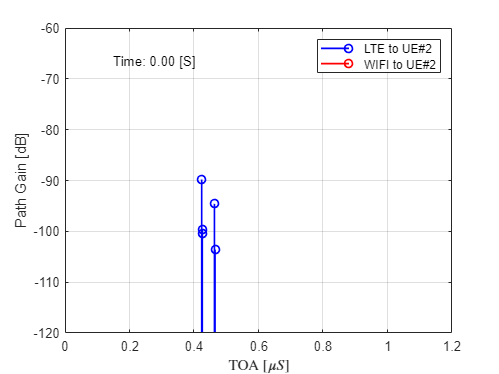

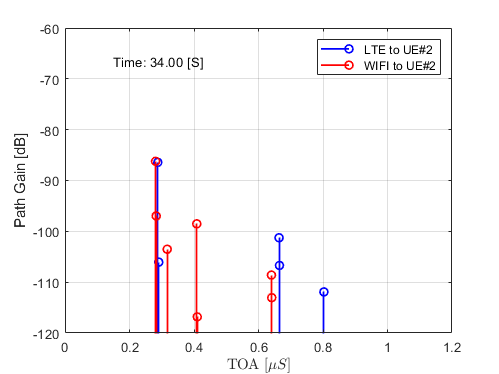

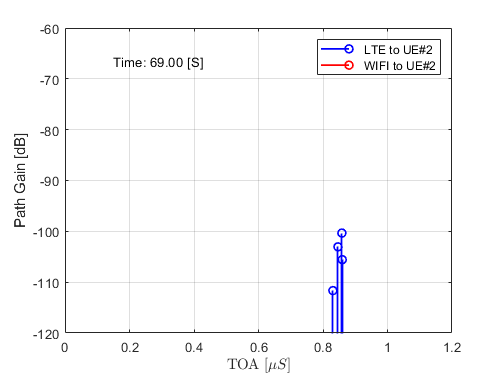

TxID = [1 2];
RxID = 4;
snapshots = [1, floor(nSnapshots/2), nSnapshots]; 
toa_scale_factor=1e6;
colors = ['b'; 'r';'g';'m'; 'c'; 'k'; 'b'; 'y'];

for snapshotIdx = 1 : numel(snapshots)
    figure
    legends = strings(1,1);
    legendsIdx = 1;
    for TxIdx = 1 : numel(TxID)
        for RxIdx = 1 : numel(RxID)
            Tx = (TxID(TxIdx));
            Rx = (RxID(RxIdx));

            if size(chMatrix{Tx,Rx,snapshots(snapshotIdx)},1) > 0
                
                    stem((chMatrix{Tx,Rx,snapshots(snapshotIdx)}.tau)*toa_scale_factor, ...
                        mag2db(abs(chMatrix{Tx,Rx,snapshots(snapshotIdx)}.h)),'BaseValue',(-150), ...
                        'Color',colors((TxIdx-1)*numel(RxID)+RxIdx),'LineWidth',1.25);

                    legends(legendsIdx) = sprintf("%s to %s",parameters.nodes.names{Tx},parameters.nodes.names{Rx});
                    legend(legends);
                    legendsIdx = legendsIdx + 1;
              
            else
                stem([],[]);
            end

            hold on
        end
    end

    hold off
    ylim([-120,-60])
    xlim([0,1.2])
    ylabel('Path Gain [dB]');
    xlabel('TOA [$\mu S$]','Interpreter','latex');
    grid on
    text(xlim*[7/8;1/8],ylim*[1/8;7/8]+1,sprintf('Time: %.2f [S]',Time(snapshots(snapshotIdx))*1e-3));

end

### Plot time-varing CIR (multi-link)

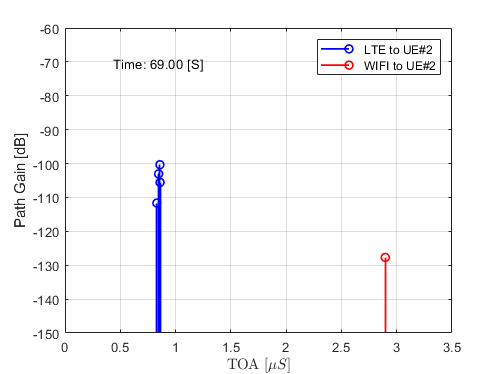

TxID = [1, 2];
RxID = 4;
toa_scale_factor=1e6;
colors = ['b'; 'r';'g';'m'; 'c'; 'k'; 'b'; 'y'];
nPaths = 20;

for snapshotIdx = 1 : size(chMatrix,3)
    figure(5)
    %set(gcf,'Visible','on')    % for external figure for recording
    legends = strings(1,1);
    legendsIdx = 1;
    for TxIdx = 1 : numel(TxID)
        for RxIdx = 1 : numel(RxID)
            Tx = TxID(TxIdx);
            Rx = RxID(RxIdx);

            if size(chMatrix{Tx,Rx,snapshotIdx},1) > 0
                
                    stem((chMatrix{Tx,Rx,snapshotIdx}.tau)*toa_scale_factor, ...
                        mag2db(abs(chMatrix{Tx,Rx,snapshotIdx}.h)),'BaseValue',(-150), ...
                        'Color',colors((TxIdx-1)*numel(RxID)+RxIdx),'LineWidth',1.25);

                    legends(legendsIdx) = sprintf("%s to %s",parameters.nodes.names{Tx},parameters.nodes.names{Rx});
                    legend(legends);
                    legendsIdx = legendsIdx + 1;
               
            else
                stem([],[]);
            end

            hold on
        end
    end

    hold off
    ylim([-150,-60])
    xlim([0,3.5])
    ylabel('Path Gain [dB]');
    xlabel('TOA [$$\mu S$$]','Interpreter','latex');
    grid on
    text(xlim*[7/8;1/8],ylim*[1/8;7/8]+1,sprintf('Time: %.2f [S]',Time(snapshotIdx)*1e-3));

    if visualization
    if size(chData{1,snapshotIdx},2)>0
        clearMap(viewer)

        txs(TxID(1)).Latitude = coordinates(TxID(1),1,snapshotIdx);
        txs(TxID(1)).Longitude = coordinates(TxID(1),2,snapshotIdx);
        txs(TxID(1)).AntennaHeight = coordinates(TxID(1),3,snapshotIdx);

        rxs(RxID(1)).Latitude = coordinates(RxID(1),1,snapshotIdx);
        rxs(RxID(1)).Longitude = coordinates(RxID(1),2,snapshotIdx);
        rxs(RxID(1)).AntennaHeight = coordinates(RxID(1),3,snapshotIdx);

        show(txs(Tx),'ShowAntennaHeight', true)
        show(rxs(Rx),'ShowAntennaHeight', true)

        rays = chData{TxID(1),RxID(1),snapshotIdx};
        plot(rays(:,1:min(size(rays,2),nPaths)),'Type', 'pathloss');
    end
    end
    ffRatio = 16;               % Fast Forward ratio
    pause(parameters.Ts/ffRatio);   
    
    

end

## Time evolution of paths

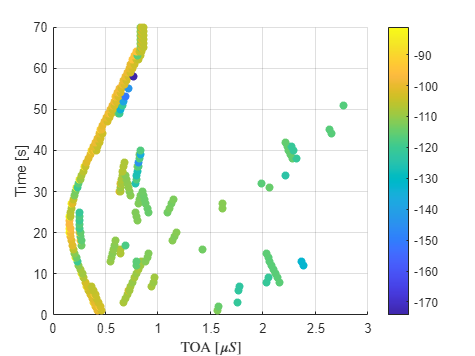

TxID = 1;
RxID = 4;
toa_scale_factor=1e6;

figure(6)
for snapshotIdx = 1:size(chMatrix,3)
    scatter( chMatrix{TxID,RxID,snapshotIdx}.tau * toa_scale_factor, ...
             ones(size(chMatrix{TxID,RxID,snapshotIdx}.tau)) * parameters.Ts * snapshotIdx, [], ...
             mag2db(abs(chMatrix{TxID,RxID,snapshotIdx}.h)) , 'filled');
    hold on
end
colorbar
grid on
xlabel('TOA [$\mu S$]','Interpreter','latex');
ylabel('Time [s]')

### Generate path loss matrix

plMatrix = nan(size(chMatrix));

for snapshotIdx = 1 : size(chMatrix,3)
    for TxIdx = 1 : size(chMatrix,1)
        for RxIdx = 1 : size(chMatrix,2)

            if size(chMatrix{Tx,Rx,snapshotIdx},1) > 0
                plMatrix(TxIdx,RxIdx,snapshotIdx) = -mag2db(sum(abs(chMatrix{TxIdx,RxIdx,snapshotIdx}.h)));
            end

            
        end
    end

end


### Plot path loss

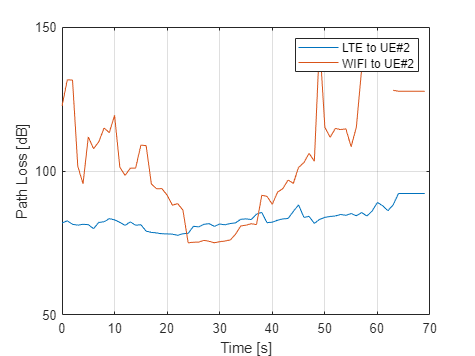


TxID = [1, 2];
RxID = 4;

% plot Path Loss (using plMatrix)
figure (7)
legends = strings(numel(TxID)*numel(RxID),1);
for TxIdx = 1 : numel(TxID)

    for RxIdx = 1 : numel(RxID)
        Tx = (TxID(TxIdx));
        Rx = (RxID(RxIdx));

        PL = plMatrix(Tx,Rx,:);

        plot(Time/1000,PL(:));
        hold on
        legends((TxIdx-1)*numel(RxID)+RxIdx) = sprintf("%s to %s",parameters.nodes.names{Tx},parameters.nodes.names{Rx});

    end

end
legend(legends);
ylabel("Path Loss [dB]");
xlabel("Time [s]");
grid on;
ylim([50,150])

## Channel tap approximation

Approximate the channels to the four taps for emulation on Colosseum

tic
[chMatrix_hat, plMatrix_hat] = chApproximation(chMatrix,'elevation','NLOS');


Snapshot: 1 of 70 ,Tx: 1, Rx: 1 


Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 28).
Elapsed time is 53.348728 seconds.

Snapshot: 1 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.408435 seconds.

Snapshot: 1 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.471718 seconds.



Snapshot: 1 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.524866 seconds.

Snapshot: 1 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.484392 seconds.



Snapshot: 1 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.505255 seconds.

Snapshot: 1 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.724451 seconds.

Snapshot: 1 of 70 ,Tx: 2, Rx: 3 

Snapshot: 1 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000365 seconds.

Snapshot: 1 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.555708 seconds.

Snapshot: 1 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.000393 seconds.



Snapshot: 1 of 70 ,Tx: 3, Rx: 2 

Snapshot: 1 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.727014 seconds.



Snapshot: 1 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.000238 seconds.



Snapshot: 1 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.580452 seconds.

Snapshot: 1 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.399055 seconds.

Snapshot: 1 of 70 ,Tx: 4, Rx: 2 

Snapshot: 1 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.000276 seconds.



Snapshot: 1 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.516368 seconds.

Snapshot: 1 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.436155 seconds.



Snapshot: 1 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.434569 seconds.



Snapshot: 1 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.596709 seconds.

Snapshot: 1 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.604704 seconds.

Snapshot: 1 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.506952 seconds.



Snapshot: 1 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.886974 seconds.

Snapshot: 2 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.873506 seconds.

Snapshot: 2 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.397526 seconds.

Snapshot: 2 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.383687 seconds.



Snapshot: 2 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.402148 seconds.



Snapshot: 2 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.497707 seconds.



Snapshot: 2 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.522258 seconds.

Snapshot: 2 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.720284 seconds.

Snapshot: 2 of 70 ,Tx: 2, Rx: 3 

Snapshot: 2 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000819 seconds.

Snapshot: 2 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.601547 seconds.

Snapshot: 2 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.000566 seconds.



Snapshot: 2 of 70 ,Tx: 3, Rx: 2 

Snapshot: 2 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.744229 seconds.



Snapshot: 2 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.000009 seconds.

Snapshot: 2 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.546074 seconds.

Snapshot: 2 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.440910 seconds.



Snapshot: 2 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000086 seconds.

Snapshot: 2 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.000009 seconds.



Snapshot: 2 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.638601 seconds.

Snapshot: 2 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.610941 seconds.

Snapshot: 2 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.467085 seconds.



Snapshot: 2 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.556569 seconds.

Snapshot: 2 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.537913 seconds.

Snapshot: 2 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.547034 seconds.

Snapshot: 2 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.814068 seconds.

Snapshot: 3 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.896236 seconds.

Snapshot: 3 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.393760 seconds.

Snapshot: 3 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.400207 seconds.



Snapshot: 3 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.469570 seconds.

Snapshot: 3 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.408273 seconds.

Snapshot: 3 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.501320 seconds.

Snapshot: 3 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.731620 seconds.

Snapshot: 3 of 70 ,Tx: 2, Rx: 3 

Snapshot: 3 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000010 seconds.

Snapshot: 3 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.576250 seconds.

Snapshot: 3 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.000009 seconds.



Snapshot: 3 of 70 ,Tx: 3, Rx: 2 

Snapshot: 3 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.702722 seconds.



Snapshot: 3 of 70 ,Tx: 3, Rx: 4 

Snapshot: 3 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.556206 seconds.

Snapshot: 3 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.493552 seconds.

Snapshot: 3 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000009 seconds.

Snapshot: 3 of 70 ,Tx: 4, Rx: 3 

Snapshot: 3 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.588751 seconds.

Snapshot: 3 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.505815 seconds.

Snapshot: 3 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.439909 seconds.

Snapshot: 3 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.604336 seconds.

Snapshot: 3 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.452728 seconds.

Snapshot: 3 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.524259 seconds.

Snapshot: 3 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.801823 seconds.



Snapshot: 4 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.901491 seconds.

Snapshot: 4 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.408325 seconds.

Snapshot: 4 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000009 seconds.



Snapshot: 4 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.442054 seconds.



Snapshot: 4 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.413251 seconds.



Snapshot: 4 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.458648 seconds.

Snapshot: 4 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.707653 seconds.

Snapshot: 4 of 70 ,Tx: 2, Rx: 3 

Snapshot: 4 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000009 seconds.



Snapshot: 4 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.579260 seconds.

Snapshot: 4 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.000009 seconds.



Snapshot: 4 of 70 ,Tx: 3, Rx: 2 

Snapshot: 4 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.756473 seconds.



Snapshot: 4 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.000008 seconds.



Snapshot: 4 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.504494 seconds.



Snapshot: 4 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.406777 seconds.



Snapshot: 4 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000009 seconds.



Snapshot: 4 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 4 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.656919 seconds.



Snapshot: 4 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.492379 seconds.

Snapshot: 4 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.407755 seconds.



Snapshot: 4 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.551068 seconds.

Snapshot: 4 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.396489 seconds.



Snapshot: 4 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.495430 seconds.

Snapshot: 4 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.824540 seconds.

Snapshot: 5 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.912916 seconds.

Snapshot: 5 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.406610 seconds.

Snapshot: 5 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.

Snapshot: 5 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.406759 seconds.



Snapshot: 5 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.500251 seconds.



Snapshot: 5 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.458619 seconds.

Snapshot: 5 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.687772 seconds.

Snapshot: 5 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000009 seconds.

Snapshot: 5 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.487496 seconds.

Snapshot: 5 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.535819 seconds.

Snapshot: 5 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.000008 seconds.

Snapshot: 5 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.000008 seconds.

Snapshot: 5 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.788758 seconds.



Snapshot: 5 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.000009 seconds.



Snapshot: 5 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.385572 seconds.



Snapshot: 5 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.397031 seconds.



Snapshot: 5 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.426008 seconds.

Snapshot: 5 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.000009 seconds.



Snapshot: 5 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.715706 seconds.



Snapshot: 5 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.000009 seconds.



Snapshot: 5 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.490742 seconds.



Snapshot: 5 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.571931 seconds.

Snapshot: 5 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.504462 seconds.

Snapshot: 5 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.000009 seconds.



Snapshot: 5 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.793079 seconds.



Snapshot: 6 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.878748 seconds.

Snapshot: 6 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.405394 seconds.

Snapshot: 6 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000009 seconds.



Snapshot: 6 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.479620 seconds.

Snapshot: 6 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.405511 seconds.



Snapshot: 6 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.477787 seconds.

Snapshot: 6 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.709939 seconds.

Snapshot: 6 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.

Snapshot: 6 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000009 seconds.

Snapshot: 6 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.593200 seconds.

Snapshot: 6 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.000009 seconds.



Snapshot: 6 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.000008 seconds.

Snapshot: 6 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.661191 seconds.



Snapshot: 6 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.391033 seconds.



Snapshot: 6 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.452656 seconds.



Snapshot: 6 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.470400 seconds.

Snapshot: 6 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000008 seconds.

Snapshot: 6 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 6 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.681530 seconds.



Snapshot: 6 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.447475 seconds.



Snapshot: 6 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.413003 seconds.



Snapshot: 6 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.589835 seconds.

Snapshot: 6 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 6 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.399172 seconds.



Snapshot: 6 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.827629 seconds.

Snapshot: 7 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.862483 seconds.

Snapshot: 7 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.397182 seconds.

Snapshot: 7 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 7 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.534134 seconds.

Snapshot: 7 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.449062 seconds.



Snapshot: 7 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.485989 seconds.

Snapshot: 7 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.702759 seconds.

Snapshot: 7 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.434304 seconds.

Snapshot: 7 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000009 seconds.

Snapshot: 7 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.556009 seconds.

Snapshot: 7 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 7 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.380620 seconds.



Snapshot: 7 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.786490 seconds.

Snapshot: 7 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.417507 seconds.



Snapshot: 7 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.571467 seconds.

Snapshot: 7 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.433616 seconds.

Snapshot: 7 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000009 seconds.

Snapshot: 7 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.423501 seconds.



Snapshot: 7 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.676933 seconds.



Snapshot: 7 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.411102 seconds.

Snapshot: 7 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.410918 seconds.



Snapshot: 7 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.552963 seconds.

Snapshot: 7 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.595130 seconds.

Snapshot: 7 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.513147 seconds.

Snapshot: 7 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.811693 seconds.



Snapshot: 8 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.872463 seconds.

Snapshot: 8 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.414241 seconds.

Snapshot: 8 of 70 ,Tx: 1, Rx: 3 

Snapshot: 8 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.532541 seconds.

Snapshot: 8 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.000008 seconds.



Snapshot: 8 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.496778 seconds.

Snapshot: 8 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.701257 seconds.

Snapshot: 8 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.493929 seconds.

Snapshot: 8 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000009 seconds.

Snapshot: 8 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.623805 seconds.

Snapshot: 8 of 70 ,Tx: 3, Rx: 1 

Snapshot: 8 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.424408 seconds.

Snapshot: 8 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.559964 seconds.



Snapshot: 8 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.549244 seconds.

Snapshot: 8 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.566420 seconds.

Snapshot: 8 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.486806 seconds.



Snapshot: 8 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000008 seconds.

Snapshot: 8 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.493795 seconds.



Snapshot: 8 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.710700 seconds.



Snapshot: 8 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.000008 seconds.



Snapshot: 8 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000007 seconds.



Snapshot: 8 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.616445 seconds.

Snapshot: 8 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.622816 seconds.

Snapshot: 8 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.472836 seconds.



Snapshot: 8 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.822176 seconds.

Snapshot: 9 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.879145 seconds.

Snapshot: 9 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.399127 seconds.

Snapshot: 9 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.508435 seconds.



Snapshot: 9 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.508138 seconds.

Snapshot: 9 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.000013 seconds.



Snapshot: 9 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.491281 seconds.

Snapshot: 9 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.718857 seconds.

Snapshot: 9 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.540556 seconds.

Snapshot: 9 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000009 seconds.



Snapshot: 9 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.706775 seconds.

Snapshot: 9 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.424732 seconds.



Snapshot: 9 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.589372 seconds.

Snapshot: 9 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.762470 seconds.



Snapshot: 9 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.594799 seconds.

Snapshot: 9 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.541016 seconds.

Snapshot: 9 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.395738 seconds.



Snapshot: 9 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000008 seconds.

Snapshot: 9 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.672865 seconds.

Snapshot: 9 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.730269 seconds.



Snapshot: 9 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.424102 seconds.



Snapshot: 9 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000009 seconds.



Snapshot: 9 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.688794 seconds.

Snapshot: 9 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.586372 seconds.

Snapshot: 9 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.435339 seconds.



Snapshot: 9 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.826243 seconds.

Snapshot: 10 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.890962 seconds.

Snapshot: 10 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.393524 seconds.

Snapshot: 10 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.428942 seconds.

Snapshot: 10 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.403767 seconds.

Snapshot: 10 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.000009 seconds.



Snapshot: 10 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.473770 seconds.

Snapshot: 10 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.711497 seconds.

Snapshot: 10 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.495977 seconds.



Snapshot: 10 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000008 seconds.



Snapshot: 10 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.683117 seconds.

Snapshot: 10 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 10 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.474810 seconds.



Snapshot: 10 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.555916 seconds.

Snapshot: 10 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.645361 seconds.

Snapshot: 10 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.509932 seconds.

Snapshot: 10 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.409429 seconds.

Snapshot: 10 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000014 seconds.

Snapshot: 10 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.544230 seconds.

Snapshot: 10 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.678551 seconds.

Snapshot: 10 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.370553 seconds.

Snapshot: 10 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000010 seconds.



Snapshot: 10 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.618335 seconds.

Snapshot: 10 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.440318 seconds.

Snapshot: 10 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.430584 seconds.

Snapshot: 10 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.885712 seconds.

Snapshot: 11 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.888679 seconds.

Snapshot: 11 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.386353 seconds.

Snapshot: 11 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.

Snapshot: 11 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.409594 seconds.



Snapshot: 11 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.000009 seconds.



Snapshot: 11 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.471590 seconds.

Snapshot: 11 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.729191 seconds.

Snapshot: 11 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.467315 seconds.

Snapshot: 11 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000008 seconds.

Snapshot: 11 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.689601 seconds.

Snapshot: 11 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.000008 seconds.

Snapshot: 11 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.422268 seconds.

Snapshot: 11 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.692535 seconds.

Snapshot: 11 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.632451 seconds.

Snapshot: 11 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.588521 seconds.

Snapshot: 11 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.415175 seconds.



Snapshot: 11 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000009 seconds.

Snapshot: 11 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.721070 seconds.

Snapshot: 11 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.597496 seconds.

Snapshot: 11 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.430379 seconds.



Snapshot: 11 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000009 seconds.



Snapshot: 11 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.677953 seconds.

Snapshot: 11 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.610859 seconds.

Snapshot: 11 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.392047 seconds.



Snapshot: 11 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.883670 seconds.



Snapshot: 12 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.876270 seconds.

Snapshot: 12 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.401067 seconds.

Snapshot: 12 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.

Snapshot: 12 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.562066 seconds.

Snapshot: 12 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.000008 seconds.



Snapshot: 12 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.473021 seconds.

Snapshot: 12 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.692466 seconds.

Snapshot: 12 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.466471 seconds.

Snapshot: 12 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000008 seconds.



Snapshot: 12 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.661750 seconds.

Snapshot: 12 of 70 ,Tx: 3, Rx: 1 

Snapshot: 12 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.479333 seconds.

Snapshot: 12 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.673601 seconds.

Snapshot: 12 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.571822 seconds.

Snapshot: 12 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.615843 seconds.

Snapshot: 12 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.479073 seconds.

Snapshot: 12 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000010 seconds.



Snapshot: 12 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.596986 seconds.

Snapshot: 12 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.712083 seconds.



Snapshot: 12 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.382060 seconds.



Snapshot: 12 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000007 seconds.



Snapshot: 12 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.653906 seconds.

Snapshot: 12 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.621881 seconds.

Snapshot: 12 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.404670 seconds.



Snapshot: 12 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.893290 seconds.



Snapshot: 13 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.901830 seconds.

Snapshot: 13 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.390883 seconds.

Snapshot: 13 of 70 ,Tx: 1, Rx: 3 

Snapshot: 13 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.549733 seconds.

Snapshot: 13 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.000008 seconds.



Snapshot: 13 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.473737 seconds.

Snapshot: 13 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.710154 seconds.

Snapshot: 13 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.504875 seconds.

Snapshot: 13 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.460719 seconds.



Snapshot: 13 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.645286 seconds.

Snapshot: 13 of 70 ,Tx: 3, Rx: 1 

Snapshot: 13 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.483164 seconds.

Snapshot: 13 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.712176 seconds.

Snapshot: 13 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.615375 seconds.

Snapshot: 13 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.607071 seconds.

Snapshot: 13 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.576367 seconds.

Snapshot: 13 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.409232 seconds.

Snapshot: 13 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.765114 seconds.

Snapshot: 13 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.690407 seconds.

Snapshot: 13 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.402911 seconds.



Snapshot: 13 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 13 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.696241 seconds.

Snapshot: 13 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.551059 seconds.



Snapshot: 13 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.422378 seconds.



Snapshot: 13 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.901377 seconds.



Snapshot: 14 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.899427 seconds.

Snapshot: 14 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.399132 seconds.

Snapshot: 14 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000009 seconds.



Snapshot: 14 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.457184 seconds.

Snapshot: 14 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.373453 seconds.



Snapshot: 14 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.476745 seconds.

Snapshot: 14 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.701810 seconds.

Snapshot: 14 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.426440 seconds.

Snapshot: 14 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000008 seconds.



Snapshot: 14 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.646946 seconds.

Snapshot: 14 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.385903 seconds.



Snapshot: 14 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.442000 seconds.

Snapshot: 14 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.729194 seconds.

Snapshot: 14 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.556975 seconds.

Snapshot: 14 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.583764 seconds.

Snapshot: 14 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.488849 seconds.

Snapshot: 14 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000009 seconds.



Snapshot: 14 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.765643 seconds.

Snapshot: 14 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.650176 seconds.



Snapshot: 14 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.522925 seconds.

Snapshot: 14 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000009 seconds.



Snapshot: 14 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.656581 seconds.

Snapshot: 14 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.596992 seconds.

Snapshot: 14 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.000009 seconds.



Snapshot: 14 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.913827 seconds.

Snapshot: 15 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.901308 seconds.

Snapshot: 15 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.418628 seconds.

Snapshot: 15 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000009 seconds.



Snapshot: 15 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.545988 seconds.

Snapshot: 15 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.000008 seconds.



Snapshot: 15 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.500144 seconds.

Snapshot: 15 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.740041 seconds.

Snapshot: 15 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.443500 seconds.



Snapshot: 15 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000008 seconds.



Snapshot: 15 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.669493 seconds.

Snapshot: 15 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 15 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.448257 seconds.

Snapshot: 15 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.698015 seconds.

Snapshot: 15 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.496865 seconds.

Snapshot: 15 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.741024 seconds.

Snapshot: 15 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.580742 seconds.

Snapshot: 15 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000008 seconds.



Snapshot: 15 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.517469 seconds.

Snapshot: 15 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.580320 seconds.

Snapshot: 15 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.371335 seconds.



Snapshot: 15 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000009 seconds.



Snapshot: 15 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.675963 seconds.

Snapshot: 15 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.716256 seconds.

Snapshot: 15 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.000008 seconds.



Snapshot: 15 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.926342 seconds.



Snapshot: 16 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.858170 seconds.

Snapshot: 16 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.390609 seconds.

Snapshot: 16 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.396317 seconds.



Snapshot: 16 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.488975 seconds.

Snapshot: 16 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.000008 seconds.



Snapshot: 16 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.488302 seconds.

Snapshot: 16 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.730832 seconds.

Snapshot: 16 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.556003 seconds.

Snapshot: 16 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000008 seconds.

Snapshot: 16 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.666865 seconds.

Snapshot: 16 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.423272 seconds.



Snapshot: 16 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.462017 seconds.

Snapshot: 16 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.523875 seconds.

Snapshot: 16 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.539899 seconds.

Snapshot: 16 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.762885 seconds.

Snapshot: 16 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000008 seconds.

Snapshot: 16 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000007 seconds.



Snapshot: 16 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.543201 seconds.

Snapshot: 16 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.724003 seconds.

Snapshot: 16 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.451593 seconds.

Snapshot: 16 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 16 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.716156 seconds.

Snapshot: 16 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.724846 seconds.

Snapshot: 16 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.474273 seconds.



Snapshot: 16 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.890224 seconds.



Snapshot: 17 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.900600 seconds.

Snapshot: 17 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.416795 seconds.

Snapshot: 17 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.620495 seconds.

Snapshot: 17 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.413100 seconds.

Snapshot: 17 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.000008 seconds.

Snapshot: 17 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.486331 seconds.

Snapshot: 17 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.723301 seconds.

Snapshot: 17 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.516786 seconds.

Snapshot: 17 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000007 seconds.

Snapshot: 17 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.673771 seconds.

Snapshot: 17 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.504612 seconds.

Snapshot: 17 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.560944 seconds.

Snapshot: 17 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.485882 seconds.

Snapshot: 17 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.533382 seconds.

Snapshot: 17 of 70 ,Tx: 3, Rx: 5 


Snapshot: 18 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.501053 seconds.

Snapshot: 18 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.737028 seconds.

Snapshot: 18 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.510832 seconds.

Snapshot: 18 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000008 seconds.



Snapshot: 18 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.645573 seconds.

Snapshot: 18 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.473599 seconds.

Snapshot: 18 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.534329 seconds.

Snapshot: 18 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.487089 seconds.

Snapshot: 18 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.540212 seconds.

Snapshot: 18 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.809132 seconds.

Snapshot: 18 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.392651 seconds.

Snapshot: 18 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000008 seconds.



Snapshot: 18 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.537542 seconds.

Snapshot: 18 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 1.046408 seconds.

Snapshot: 18 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.511347 seconds.

Snapshot: 18 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 18 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.681235 seconds.

Snapshot: 18 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.797589 seconds.

Snapshot: 18 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.490025 seconds.

Snapshot: 18 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.860047 seconds.



Snapshot: 19 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.885341 seconds.

Snapshot: 19 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.383038 seconds.

Snapshot: 19 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.547575 seconds.

Snapshot: 19 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.383292 seconds.



Snapshot: 19 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.000008 seconds.



Snapshot: 19 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.489953 seconds.

Snapshot: 19 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.704636 seconds.

Snapshot: 19 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.580715 seconds.

Snapshot: 19 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.385628 seconds.

Snapshot: 19 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.588654 seconds.

Snapshot: 19 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.411542 seconds.

Snapshot: 19 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.635410 seconds.

Snapshot: 19 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.657805 seconds.

Snapshot: 19 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.544896 seconds.

Snapshot: 19 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.662996 seconds.

Snapshot: 19 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.383712 seconds.



Snapshot: 19 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000010 seconds.



Snapshot: 19 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.521832 seconds.

Snapshot: 19 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.952545 seconds.

Snapshot: 19 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.488086 seconds.

Snapshot: 19 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 19 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.595508 seconds.

Snapshot: 19 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.686313 seconds.

Snapshot: 19 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.525995 seconds.

Snapshot: 19 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.860074 seconds.

Snapshot: 20 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.877362 seconds.

Snapshot: 20 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.388668 seconds.

Snapshot: 20 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.

Snapshot: 20 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.383960 seconds.

Snapshot: 20 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.000008 seconds.



Snapshot: 20 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.461845 seconds.

Snapshot: 20 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.703143 seconds.

Snapshot: 20 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.598352 seconds.

Snapshot: 20 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.431718 seconds.

Snapshot: 20 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.624598 seconds.

Snapshot: 20 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.000008 seconds.

Snapshot: 20 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.559015 seconds.

Snapshot: 20 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.634507 seconds.

Snapshot: 20 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.597076 seconds.

Snapshot: 20 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.542461 seconds.

Snapshot: 20 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 20 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.418655 seconds.

Snapshot: 20 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.555793 seconds.

Snapshot: 20 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.762037 seconds.



Snapshot: 20 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.543485 seconds.

Snapshot: 20 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 20 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.643064 seconds.

Snapshot: 20 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.582397 seconds.

Snapshot: 20 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.530948 seconds.

Snapshot: 20 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.958011 seconds.



Snapshot: 21 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.878202 seconds.

Snapshot: 21 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.403323 seconds.

Snapshot: 21 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.447517 seconds.



Snapshot: 21 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000008 seconds.



Snapshot: 21 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.000006 seconds.



Snapshot: 21 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.464766 seconds.

Snapshot: 21 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.706641 seconds.

Snapshot: 21 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.588533 seconds.

Snapshot: 21 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.436161 seconds.

Snapshot: 21 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.674712 seconds.

Snapshot: 21 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.450392 seconds.

Snapshot: 21 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.569220 seconds.

Snapshot: 21 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.689902 seconds.

Snapshot: 21 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.789399 seconds.

Snapshot: 21 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.692819 seconds.

Snapshot: 21 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000009 seconds.



Snapshot: 21 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.427690 seconds.

Snapshot: 21 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.725692 seconds.

Snapshot: 21 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.864210 seconds.

Snapshot: 21 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.478938 seconds.

Snapshot: 21 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 21 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.693642 seconds.

Snapshot: 21 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.655748 seconds.

Snapshot: 21 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.478589 seconds.

Snapshot: 21 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.922271 seconds.



Snapshot: 22 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.909394 seconds.

Snapshot: 22 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.380359 seconds.

Snapshot: 22 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.439345 seconds.

Snapshot: 22 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000008 seconds.



Snapshot: 22 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.000007 seconds.



Snapshot: 22 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.486619 seconds.

Snapshot: 22 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.712401 seconds.

Snapshot: 22 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 22 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.414881 seconds.

Snapshot: 22 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.624368 seconds.

Snapshot: 22 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.437499 seconds.

Snapshot: 22 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.382375 seconds.



Snapshot: 22 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.807120 seconds.

Snapshot: 22 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.740618 seconds.

Snapshot: 22 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.689421 seconds.

Snapshot: 22 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 22 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.485251 seconds.

Snapshot: 22 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.749412 seconds.

Snapshot: 22 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.795194 seconds.

Snapshot: 22 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.548186 seconds.

Snapshot: 22 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000009 seconds.



Snapshot: 22 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.594164 seconds.

Snapshot: 22 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.738262 seconds.

Snapshot: 22 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.556505 seconds.



Snapshot: 22 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.978077 seconds.



Snapshot: 23 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.884103 seconds.

Snapshot: 23 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.392705 seconds.

Snapshot: 23 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.404889 seconds.

Snapshot: 23 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.399736 seconds.



Snapshot: 23 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.000008 seconds.



Snapshot: 23 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.487856 seconds.

Snapshot: 23 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.701268 seconds.

Snapshot: 23 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 23 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.469281 seconds.

Snapshot: 23 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.583337 seconds.

Snapshot: 23 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.461185 seconds.

Snapshot: 23 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.000008 seconds.



Snapshot: 23 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.677181 seconds.



Snapshot: 23 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.776428 seconds.

Snapshot: 23 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.603574 seconds.

Snapshot: 23 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.422983 seconds.

Snapshot: 23 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.424578 seconds.

Snapshot: 23 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.691284 seconds.

Snapshot: 23 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.767943 seconds.

Snapshot: 23 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.524735 seconds.

Snapshot: 23 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 23 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.608334 seconds.

Snapshot: 23 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.641463 seconds.

Snapshot: 23 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.557062 seconds.

Snapshot: 23 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.966950 seconds.



Snapshot: 24 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.900661 seconds.

Snapshot: 24 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.403254 seconds.

Snapshot: 24 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 24 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.453842 seconds.



Snapshot: 24 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.000008 seconds.



Snapshot: 24 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.485449 seconds.

Snapshot: 24 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.713948 seconds.

Snapshot: 24 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.383144 seconds.



Snapshot: 24 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.555640 seconds.

Snapshot: 24 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.639117 seconds.

Snapshot: 24 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 24 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.000006 seconds.



Snapshot: 24 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.837466 seconds.

Snapshot: 24 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.633741 seconds.



Snapshot: 24 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.578304 seconds.

Snapshot: 24 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.388924 seconds.



Snapshot: 24 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.565916 seconds.

Snapshot: 24 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.661761 seconds.



Snapshot: 24 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.734542 seconds.

Snapshot: 24 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.547502 seconds.

Snapshot: 24 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 24 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.584067 seconds.

Snapshot: 24 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.571455 seconds.

Snapshot: 24 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.554661 seconds.

Snapshot: 24 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.886653 seconds.



Snapshot: 25 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.871847 seconds.

Snapshot: 25 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.373390 seconds.

Snapshot: 25 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.573081 seconds.

Snapshot: 25 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.461945 seconds.

Snapshot: 25 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.000008 seconds.



Snapshot: 25 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.487689 seconds.

Snapshot: 25 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.754011 seconds.

Snapshot: 25 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.523215 seconds.

Snapshot: 25 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.595627 seconds.

Snapshot: 25 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.650338 seconds.

Snapshot: 25 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.579599 seconds.

Snapshot: 25 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.422714 seconds.

Snapshot: 25 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.772519 seconds.

Snapshot: 25 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.627673 seconds.



Snapshot: 25 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.541770 seconds.

Snapshot: 25 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.463062 seconds.

Snapshot: 25 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.555968 seconds.

Snapshot: 25 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.666500 seconds.

Snapshot: 25 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.853544 seconds.

Snapshot: 25 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.642678 seconds.

Snapshot: 25 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 25 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.611790 seconds.

Snapshot: 25 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.571362 seconds.

Snapshot: 25 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.645507 seconds.



Snapshot: 25 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.872715 seconds.

Snapshot: 26 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.870878 seconds.

Snapshot: 26 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.396051 seconds.

Snapshot: 26 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.375451 seconds.



Snapshot: 26 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.350009 seconds.

Snapshot: 26 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.000008 seconds.



Snapshot: 26 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.489838 seconds.

Snapshot: 26 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.733269 seconds.

Snapshot: 26 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.518986 seconds.

Snapshot: 26 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.635814 seconds.

Snapshot: 26 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.665710 seconds.

Snapshot: 26 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.526695 seconds.



Snapshot: 26 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.432587 seconds.

Snapshot: 26 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.889444 seconds.

Snapshot: 26 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.562691 seconds.

Snapshot: 26 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.525093 seconds.

Snapshot: 26 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.343034 seconds.

Snapshot: 26 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.606596 seconds.

Snapshot: 26 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.550943 seconds.

Snapshot: 26 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.748367 seconds.

Snapshot: 26 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.736030 seconds.

Snapshot: 26 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000009 seconds.



Snapshot: 26 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.692089 seconds.

Snapshot: 26 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.529283 seconds.

Snapshot: 26 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.734650 seconds.

Snapshot: 26 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.901229 seconds.

Snapshot: 27 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.879438 seconds.

Snapshot: 27 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.397730 seconds.

Snapshot: 27 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.

Snapshot: 27 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.401432 seconds.

Snapshot: 27 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.386214 seconds.



Snapshot: 27 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.478136 seconds.

Snapshot: 27 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.714821 seconds.

Snapshot: 27 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.514996 seconds.

Snapshot: 27 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.613012 seconds.

Snapshot: 27 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.628947 seconds.

Snapshot: 27 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.000008 seconds.

Snapshot: 27 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.000007 seconds.



Snapshot: 27 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.695657 seconds.

Snapshot: 27 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.623876 seconds.

Snapshot: 27 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.469041 seconds.



Snapshot: 27 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.422582 seconds.

Snapshot: 27 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.662952 seconds.

Snapshot: 27 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.572671 seconds.

Snapshot: 27 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.793422 seconds.

Snapshot: 27 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.921182 seconds.

Snapshot: 27 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 27 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.612947 seconds.

Snapshot: 27 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.453830 seconds.



Snapshot: 27 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.873669 seconds.

Snapshot: 27 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.881620 seconds.

Snapshot: 28 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.883134 seconds.

Snapshot: 28 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.384894 seconds.

Snapshot: 28 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.

Snapshot: 28 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.354428 seconds.

Snapshot: 28 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.382771 seconds.



Snapshot: 28 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.482896 seconds.

Snapshot: 28 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.729288 seconds.

Snapshot: 28 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.487038 seconds.

Snapshot: 28 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.618672 seconds.

Snapshot: 28 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.617577 seconds.

Snapshot: 28 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.000008 seconds.

Snapshot: 28 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.479811 seconds.

Snapshot: 28 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.722048 seconds.

Snapshot: 28 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.619135 seconds.

Snapshot: 28 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.529057 seconds.

Snapshot: 28 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.378550 seconds.

Snapshot: 28 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.607659 seconds.

Snapshot: 28 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.639303 seconds.

Snapshot: 28 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.747234 seconds.

Snapshot: 28 of 70 ,Tx: 4, Rx: 5 


Snapshot: 28 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.684830 seconds.

Snapshot: 28 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.527197 seconds.

Snapshot: 28 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.781712 seconds.

Snapshot: 28 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.848621 seconds.



Snapshot: 29 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.896733 seconds.

Snapshot: 29 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.407372 seconds.

Snapshot: 29 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 29 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.487366 seconds.

Snapshot: 29 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.532270 seconds.

Snapshot: 29 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.457658 seconds.

Snapshot: 29 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.684164 seconds.

Snapshot: 29 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.

Snapshot: 29 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.548579 seconds.

Snapshot: 29 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.602879 seconds.

Snapshot: 29 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 29 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.000008 seconds.

Snapshot: 29 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.730249 seconds.

Snapshot: 29 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.559279 seconds.

Snapshot: 29 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.472530 seconds.

Snapshot: 29 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.469111 seconds.

Snapshot: 29 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.654945 seconds.

Snapshot: 29 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.533901 seconds.

Snapshot: 29 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.778504 seconds.

Snapshot: 29 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.819882 seconds.

Snapshot: 29 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.451519 seconds.

Snapshot: 29 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.907071 seconds.

Snapshot: 29 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.563725 seconds.

Snapshot: 29 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 7.135620 seconds.

Snapshot: 29 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 1.909719 seconds.



Snapshot: 30 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 1.106402 seconds.

Snapshot: 30 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.457905 seconds.

Snapshot: 30 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000010 seconds.

Snapshot: 30 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.572195 seconds.

Snapshot: 30 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.560987 seconds.

Snapshot: 30 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.477253 seconds.

Snapshot: 30 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.697481 seconds.

Snapshot: 30 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 30 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.593098 seconds.

Snapshot: 30 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.616350 seconds.

Snapshot: 30 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.000008 seconds.

Snapshot: 30 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.000007 seconds.



Snapshot: 30 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.719904 seconds.

Snapshot: 30 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.501611 seconds.

Snapshot: 30 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.605816 seconds.

Snapshot: 30 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.478237 seconds.

Snapshot: 30 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.638523 seconds.

Snapshot: 30 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.517171 seconds.

Snapshot: 30 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.714775 seconds.

Snapshot: 30 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.707951 seconds.

Snapshot: 30 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.477523 seconds.

Snapshot: 30 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.629381 seconds.

Snapshot: 30 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.566084 seconds.

Snapshot: 30 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.758185 seconds.

Snapshot: 30 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.880193 seconds.

Snapshot: 31 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.862553 seconds.

Snapshot: 31 of 70 ,Tx: 1, Rx: 2 


Snapshot: 31 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.455959 seconds.

Snapshot: 31 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.474479 seconds.

Snapshot: 31 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.476013 seconds.

Snapshot: 31 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.707211 seconds.

Snapshot: 31 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 31 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.532896 seconds.



Snapshot: 31 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.601418 seconds.

Snapshot: 31 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.403168 seconds.



Snapshot: 31 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.521288 seconds.

Snapshot: 31 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.766340 seconds.

Snapshot: 31 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.557631 seconds.

Snapshot: 31 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.579112 seconds.

Snapshot: 31 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.469258 seconds.

Snapshot: 31 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.537522 seconds.



Snapshot: 31 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.553364 seconds.

Snapshot: 31 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.656689 seconds.

Snapshot: 31 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.751926 seconds.

Snapshot: 31 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.551385 seconds.

Snapshot: 31 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.609438 seconds.

Snapshot: 31 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.526990 seconds.

Snapshot: 31 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.756685 seconds.

Snapshot: 31 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.885863 seconds.

Snapshot: 32 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.856206 seconds.

Snapshot: 32 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.377369 seconds.

Snapshot: 32 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 32 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.547039 seconds.

Snapshot: 32 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.559948 seconds.

Snapshot: 32 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.454414 seconds.

Snapshot: 32 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.697868 seconds.

Snapshot: 32 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 32 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.563508 seconds.

Snapshot: 32 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.623360 seconds.

Snapshot: 32 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.377608 seconds.



Snapshot: 32 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.482140 seconds.

Snapshot: 32 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.709105 seconds.

Snapshot: 32 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.521166 seconds.

Snapshot: 32 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.599078 seconds.

Snapshot: 32 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.491201 seconds.

Snapshot: 32 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.551762 seconds.

Snapshot: 32 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.409328 seconds.

Snapshot: 32 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.632690 seconds.

Snapshot: 32 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.780641 seconds.

Snapshot: 32 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.486896 seconds.

Snapshot: 32 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.651318 seconds.

Snapshot: 32 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.604647 seconds.

Snapshot: 32 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.838168 seconds.

Snapshot: 32 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.938399 seconds.



Snapshot: 33 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.877865 seconds.

Snapshot: 33 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.376804 seconds.

Snapshot: 33 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 33 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.518868 seconds.

Snapshot: 33 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.483508 seconds.

Snapshot: 33 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.496535 seconds.

Snapshot: 33 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.769110 seconds.

Snapshot: 33 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 33 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.559079 seconds.

Snapshot: 33 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.699449 seconds.

Snapshot: 33 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.389391 seconds.



Snapshot: 33 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.530187 seconds.

Snapshot: 33 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.781343 seconds.

Snapshot: 33 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.415046 seconds.



Snapshot: 33 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.634638 seconds.

Snapshot: 33 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.482642 seconds.

Snapshot: 33 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.572038 seconds.

Snapshot: 33 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.617024 seconds.



Snapshot: 33 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.725806 seconds.

Snapshot: 33 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.806459 seconds.

Snapshot: 33 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.515262 seconds.

Snapshot: 33 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.683337 seconds.

Snapshot: 33 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.536279 seconds.

Snapshot: 33 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.775754 seconds.

Snapshot: 33 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.865022 seconds.

Snapshot: 34 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 1.257317 seconds.

Snapshot: 34 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.462558 seconds.

Snapshot: 34 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 34 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 6.178478 seconds.

Snapshot: 34 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 1.417502 seconds.

Snapshot: 34 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.781076 seconds.

Snapshot: 34 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.861215 seconds.

Snapshot: 34 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 34 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.541946 seconds.

Snapshot: 34 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.630021 seconds.

Snapshot: 34 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.403732 seconds.



Snapshot: 34 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.511467 seconds.

Snapshot: 34 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.768661 seconds.

Snapshot: 34 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.374986 seconds.



Snapshot: 34 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.539739 seconds.

Snapshot: 34 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.503449 seconds.

Snapshot: 34 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.527017 seconds.

Snapshot: 34 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.378684 seconds.



Snapshot: 34 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.622878 seconds.

Snapshot: 34 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.814550 seconds.

Snapshot: 34 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.485623 seconds.

Snapshot: 34 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.626038 seconds.

Snapshot: 34 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.614553 seconds.

Snapshot: 34 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.821843 seconds.

Snapshot: 34 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.861951 seconds.



Snapshot: 35 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.878912 seconds.

Snapshot: 35 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.392619 seconds.

Snapshot: 35 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000009 seconds.



Snapshot: 35 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.399559 seconds.



Snapshot: 35 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.547791 seconds.

Snapshot: 35 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.458903 seconds.

Snapshot: 35 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.687875 seconds.

Snapshot: 35 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 35 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.480449 seconds.

Snapshot: 35 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.700179 seconds.

Snapshot: 35 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.387840 seconds.



Snapshot: 35 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.517250 seconds.

Snapshot: 35 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.788879 seconds.

Snapshot: 35 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.402227 seconds.



Snapshot: 35 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.596562 seconds.

Snapshot: 35 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.478699 seconds.

Snapshot: 35 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.516218 seconds.

Snapshot: 35 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.471275 seconds.



Snapshot: 35 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.711816 seconds.

Snapshot: 35 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.803207 seconds.

Snapshot: 35 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.521356 seconds.

Snapshot: 35 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.650280 seconds.

Snapshot: 35 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.567495 seconds.

Snapshot: 35 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.843206 seconds.

Snapshot: 35 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.942808 seconds.

Snapshot: 36 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.915264 seconds.

Snapshot: 36 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.405480 seconds.

Snapshot: 36 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 36 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.412859 seconds.

Snapshot: 36 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.578346 seconds.

Snapshot: 36 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.438959 seconds.

Snapshot: 36 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.693569 seconds.

Snapshot: 36 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 36 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.476521 seconds.

Snapshot: 36 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.623678 seconds.

Snapshot: 36 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.392492 seconds.



Snapshot: 36 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.530507 seconds.

Snapshot: 36 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.753433 seconds.

Snapshot: 36 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.000008 seconds.



Snapshot: 36 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.544921 seconds.

Snapshot: 36 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.389010 seconds.

Snapshot: 36 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.481496 seconds.

Snapshot: 36 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.389426 seconds.



Snapshot: 36 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.824428 seconds.



Snapshot: 36 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.757308 seconds.

Snapshot: 36 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.555379 seconds.

Snapshot: 36 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.653395 seconds.

Snapshot: 36 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.519623 seconds.

Snapshot: 36 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.685340 seconds.

Snapshot: 36 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.880566 seconds.



Snapshot: 37 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.906094 seconds.

Snapshot: 37 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.382378 seconds.

Snapshot: 37 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000015 seconds.



Snapshot: 37 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.516193 seconds.



Snapshot: 37 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.577963 seconds.

Snapshot: 37 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.466990 seconds.

Snapshot: 37 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.695204 seconds.

Snapshot: 37 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 37 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.420098 seconds.

Snapshot: 37 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.658635 seconds.

Snapshot: 37 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.377614 seconds.



Snapshot: 37 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.467639 seconds.

Snapshot: 37 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.732799 seconds.

Snapshot: 37 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.368673 seconds.



Snapshot: 37 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.517814 seconds.

Snapshot: 37 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.461365 seconds.



Snapshot: 37 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.506119 seconds.

Snapshot: 37 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.370084 seconds.



Snapshot: 37 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.746805 seconds.

Snapshot: 37 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.740670 seconds.

Snapshot: 37 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.546042 seconds.

Snapshot: 37 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.661533 seconds.

Snapshot: 37 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.615133 seconds.

Snapshot: 37 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.707740 seconds.

Snapshot: 37 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 1.064037 seconds.

Snapshot: 38 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.885691 seconds.

Snapshot: 38 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.392353 seconds.

Snapshot: 38 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 38 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.398688 seconds.

Snapshot: 38 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.581416 seconds.

Snapshot: 38 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.479099 seconds.

Snapshot: 38 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.715897 seconds.

Snapshot: 38 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 38 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.437111 seconds.

Snapshot: 38 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.657693 seconds.

Snapshot: 38 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.380691 seconds.



Snapshot: 38 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.501950 seconds.

Snapshot: 38 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.752565 seconds.

Snapshot: 38 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.393489 seconds.



Snapshot: 38 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.541168 seconds.

Snapshot: 38 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.417294 seconds.

Snapshot: 38 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.489362 seconds.

Snapshot: 38 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.401044 seconds.



Snapshot: 38 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.716297 seconds.

Snapshot: 38 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.636702 seconds.



Snapshot: 38 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.552837 seconds.

Snapshot: 38 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.676989 seconds.

Snapshot: 38 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.471982 seconds.



Snapshot: 38 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.632533 seconds.

Snapshot: 38 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.900857 seconds.

Snapshot: 39 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.897996 seconds.

Snapshot: 39 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.384752 seconds.

Snapshot: 39 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 39 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.381792 seconds.

Snapshot: 39 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.583220 seconds.

Snapshot: 39 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.461566 seconds.

Snapshot: 39 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.695884 seconds.

Snapshot: 39 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 39 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.468759 seconds.

Snapshot: 39 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.617300 seconds.

Snapshot: 39 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.385490 seconds.



Snapshot: 39 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.490936 seconds.

Snapshot: 39 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.766974 seconds.

Snapshot: 39 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.000008 seconds.



Snapshot: 39 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.505519 seconds.

Snapshot: 39 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.402857 seconds.

Snapshot: 39 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.393879 seconds.

Snapshot: 39 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.376244 seconds.



Snapshot: 39 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.659297 seconds.



Snapshot: 39 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.615787 seconds.

Snapshot: 39 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.529619 seconds.

Snapshot: 39 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.654160 seconds.

Snapshot: 39 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.596428 seconds.

Snapshot: 39 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.596857 seconds.

Snapshot: 39 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.862213 seconds.

Snapshot: 40 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.865561 seconds.

Snapshot: 40 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.377105 seconds.

Snapshot: 40 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 40 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.514774 seconds.

Snapshot: 40 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.549439 seconds.

Snapshot: 40 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.477026 seconds.

Snapshot: 40 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.716950 seconds.

Snapshot: 40 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 40 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.504160 seconds.



Snapshot: 40 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.584300 seconds.

Snapshot: 40 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.382247 seconds.



Snapshot: 40 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.475473 seconds.

Snapshot: 40 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.765675 seconds.

Snapshot: 40 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.400206 seconds.

Snapshot: 40 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.535710 seconds.

Snapshot: 40 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.487743 seconds.

Snapshot: 40 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.494118 seconds.



Snapshot: 40 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.476742 seconds.

Snapshot: 40 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.591847 seconds.



Snapshot: 40 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.597142 seconds.



Snapshot: 40 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.551935 seconds.

Snapshot: 40 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.632576 seconds.

Snapshot: 40 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.537292 seconds.

Snapshot: 40 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.572219 seconds.



Snapshot: 40 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.916382 seconds.

Snapshot: 41 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.892758 seconds.

Snapshot: 41 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.401705 seconds.

Snapshot: 41 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000012 seconds.



Snapshot: 41 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.521984 seconds.

Snapshot: 41 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.571323 seconds.

Snapshot: 41 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.451475 seconds.

Snapshot: 41 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.705086 seconds.

Snapshot: 41 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 41 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.479775 seconds.

Snapshot: 41 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.617008 seconds.

Snapshot: 41 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.372824 seconds.



Snapshot: 41 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.498807 seconds.

Snapshot: 41 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.777092 seconds.

Snapshot: 41 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.428708 seconds.

Snapshot: 41 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.551476 seconds.

Snapshot: 41 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.443626 seconds.



Snapshot: 41 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.553697 seconds.

Snapshot: 41 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.423836 seconds.

Snapshot: 41 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.620260 seconds.



Snapshot: 41 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.604056 seconds.

Snapshot: 41 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.556172 seconds.

Snapshot: 41 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.610472 seconds.

Snapshot: 41 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.637946 seconds.

Snapshot: 41 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.554561 seconds.

Snapshot: 41 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.886576 seconds.

Snapshot: 42 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.918451 seconds.

Snapshot: 42 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.389213 seconds.

Snapshot: 42 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 42 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.369634 seconds.



Snapshot: 42 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.548999 seconds.

Snapshot: 42 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.505958 seconds.

Snapshot: 42 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.715789 seconds.

Snapshot: 42 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000009 seconds.



Snapshot: 42 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.403492 seconds.

Snapshot: 42 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.580077 seconds.

Snapshot: 42 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.399712 seconds.



Snapshot: 42 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.495437 seconds.

Snapshot: 42 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.734215 seconds.

Snapshot: 42 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.461591 seconds.

Snapshot: 42 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.488630 seconds.

Snapshot: 42 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 42 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.444835 seconds.

Snapshot: 42 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.504570 seconds.

Snapshot: 42 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.905140 seconds.

Snapshot: 42 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.508104 seconds.

Snapshot: 42 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.576206 seconds.

Snapshot: 42 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.649426 seconds.

Snapshot: 42 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.606670 seconds.

Snapshot: 42 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.489081 seconds.

Snapshot: 42 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.839175 seconds.

Snapshot: 43 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.846100 seconds.

Snapshot: 43 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.380357 seconds.

Snapshot: 43 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 43 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000006 seconds.



Snapshot: 43 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.517337 seconds.

Snapshot: 43 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.456557 seconds.

Snapshot: 43 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.686081 seconds.

Snapshot: 43 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 43 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.416249 seconds.



Snapshot: 43 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.660931 seconds.

Snapshot: 43 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.380394 seconds.



Snapshot: 43 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.486306 seconds.

Snapshot: 43 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.745904 seconds.

Snapshot: 43 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.527062 seconds.



Snapshot: 43 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.620718 seconds.

Snapshot: 43 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 43 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.383930 seconds.



Snapshot: 43 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.555215 seconds.

Snapshot: 43 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.591937 seconds.



Snapshot: 43 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.467027 seconds.

Snapshot: 43 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.529483 seconds.

Snapshot: 43 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.665461 seconds.

Snapshot: 43 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.594812 seconds.

Snapshot: 43 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.480573 seconds.

Snapshot: 43 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.802968 seconds.

Snapshot: 44 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.883713 seconds.

Snapshot: 44 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.387977 seconds.

Snapshot: 44 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 44 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.371408 seconds.



Snapshot: 44 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.527410 seconds.

Snapshot: 44 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.451732 seconds.

Snapshot: 44 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.765348 seconds.

Snapshot: 44 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 44 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000006 seconds.



Snapshot: 44 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.637055 seconds.

Snapshot: 44 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.369426 seconds.



Snapshot: 44 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.486185 seconds.

Snapshot: 44 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.730041 seconds.

Snapshot: 44 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.592236 seconds.

Snapshot: 44 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.386040 seconds.



Snapshot: 44 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.372910 seconds.



Snapshot: 44 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000007 seconds.



Snapshot: 44 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.566707 seconds.

Snapshot: 44 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.756241 seconds.



Snapshot: 44 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.471698 seconds.

Snapshot: 44 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.535404 seconds.

Snapshot: 44 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.717796 seconds.

Snapshot: 44 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.438388 seconds.



Snapshot: 44 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.438719 seconds.

Snapshot: 44 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.913514 seconds.

Snapshot: 45 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.885554 seconds.

Snapshot: 45 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.382793 seconds.

Snapshot: 45 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 45 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000007 seconds.



Snapshot: 45 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.597458 seconds.

Snapshot: 45 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.472270 seconds.

Snapshot: 45 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.707727 seconds.

Snapshot: 45 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 45 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000007 seconds.



Snapshot: 45 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.656479 seconds.

Snapshot: 45 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.370229 seconds.



Snapshot: 45 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.467338 seconds.

Snapshot: 45 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.736091 seconds.

Snapshot: 45 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.596572 seconds.

Snapshot: 45 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.404165 seconds.



Snapshot: 45 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000007 seconds.



Snapshot: 45 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000007 seconds.



Snapshot: 45 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.507024 seconds.

Snapshot: 45 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.678736 seconds.

Snapshot: 45 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.448556 seconds.

Snapshot: 45 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.517142 seconds.

Snapshot: 45 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.721558 seconds.

Snapshot: 45 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.419082 seconds.



Snapshot: 45 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.428144 seconds.

Snapshot: 45 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.828565 seconds.

Snapshot: 46 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.889226 seconds.

Snapshot: 46 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.410697 seconds.

Snapshot: 46 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000012 seconds.



Snapshot: 46 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000007 seconds.

Snapshot: 46 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.532517 seconds.

Snapshot: 46 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.474856 seconds.

Snapshot: 46 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.731908 seconds.

Snapshot: 46 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 46 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000007 seconds.



Snapshot: 46 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.669578 seconds.

Snapshot: 46 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.383989 seconds.



Snapshot: 46 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.486121 seconds.

Snapshot: 46 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.742192 seconds.

Snapshot: 46 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.515093 seconds.

Snapshot: 46 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.426845 seconds.



Snapshot: 46 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000007 seconds.

Snapshot: 46 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000006 seconds.

Snapshot: 46 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.524755 seconds.

Snapshot: 46 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.707601 seconds.

Snapshot: 46 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.429356 seconds.

Snapshot: 46 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.536773 seconds.

Snapshot: 46 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.737298 seconds.

Snapshot: 46 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.356828 seconds.



Snapshot: 46 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.458354 seconds.

Snapshot: 46 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.858398 seconds.

Snapshot: 47 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.881108 seconds.

Snapshot: 47 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.389548 seconds.

Snapshot: 47 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 47 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000007 seconds.



Snapshot: 47 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.520416 seconds.

Snapshot: 47 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.479454 seconds.

Snapshot: 47 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.720098 seconds.

Snapshot: 47 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 47 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000009 seconds.



Snapshot: 47 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.660532 seconds.

Snapshot: 47 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.380980 seconds.



Snapshot: 47 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.495885 seconds.

Snapshot: 47 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.742288 seconds.

Snapshot: 47 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.588493 seconds.

Snapshot: 47 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.438193 seconds.



Snapshot: 47 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.420381 seconds.



Snapshot: 47 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000007 seconds.



Snapshot: 47 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.562059 seconds.

Snapshot: 47 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.752344 seconds.

Snapshot: 47 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.485206 seconds.



Snapshot: 47 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.502619 seconds.

Snapshot: 47 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.684840 seconds.

Snapshot: 47 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.348297 seconds.



Snapshot: 47 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.463826 seconds.



Snapshot: 47 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.894618 seconds.

Snapshot: 48 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.881241 seconds.

Snapshot: 48 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.392571 seconds.

Snapshot: 48 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 48 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000006 seconds.



Snapshot: 48 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.595364 seconds.

Snapshot: 48 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.456848 seconds.

Snapshot: 48 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.698562 seconds.

Snapshot: 48 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000009 seconds.



Snapshot: 48 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000007 seconds.



Snapshot: 48 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.659419 seconds.

Snapshot: 48 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.377293 seconds.



Snapshot: 48 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.489606 seconds.

Snapshot: 48 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.725692 seconds.

Snapshot: 48 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.568615 seconds.

Snapshot: 48 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.435167 seconds.



Snapshot: 48 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 48 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000006 seconds.



Snapshot: 48 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.509979 seconds.



Snapshot: 48 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.848495 seconds.

Snapshot: 48 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.000007 seconds.



Snapshot: 48 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.514294 seconds.

Snapshot: 48 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.682424 seconds.

Snapshot: 48 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.341323 seconds.



Snapshot: 48 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.000007 seconds.



Snapshot: 48 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.926237 seconds.

Snapshot: 49 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.866356 seconds.

Snapshot: 49 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.375341 seconds.

Snapshot: 49 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 49 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.516924 seconds.



Snapshot: 49 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.575417 seconds.

Snapshot: 49 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.478358 seconds.

Snapshot: 49 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.795718 seconds.

Snapshot: 49 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 49 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000006 seconds.



Snapshot: 49 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.661027 seconds.

Snapshot: 49 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.384762 seconds.



Snapshot: 49 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.620173 seconds.

Snapshot: 49 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.773408 seconds.

Snapshot: 49 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.977139 seconds.

Snapshot: 49 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.000007 seconds.



Snapshot: 49 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.588764 seconds.



Snapshot: 49 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000007 seconds.

Snapshot: 49 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.482764 seconds.

Snapshot: 49 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 1.077491 seconds.



Snapshot: 49 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.000007 seconds.



Snapshot: 49 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.528587 seconds.

Snapshot: 49 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.688735 seconds.

Snapshot: 49 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 49 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.000007 seconds.



Snapshot: 49 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.878984 seconds.

Snapshot: 50 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.872928 seconds.

Snapshot: 50 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.385983 seconds.

Snapshot: 50 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 50 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.458796 seconds.



Snapshot: 50 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.511583 seconds.

Snapshot: 50 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.438870 seconds.

Snapshot: 50 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.691404 seconds.

Snapshot: 50 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 50 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000008 seconds.

Snapshot: 50 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.640580 seconds.

Snapshot: 50 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.384686 seconds.



Snapshot: 50 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.465058 seconds.

Snapshot: 50 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.715041 seconds.

Snapshot: 50 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.492210 seconds.

Snapshot: 50 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.432727 seconds.



Snapshot: 50 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.409185 seconds.



Snapshot: 50 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000008 seconds.

Snapshot: 50 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.535153 seconds.

Snapshot: 50 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.532352 seconds.



Snapshot: 50 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.374883 seconds.



Snapshot: 50 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.533175 seconds.

Snapshot: 50 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.667500 seconds.

Snapshot: 50 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.393623 seconds.



Snapshot: 50 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.349575 seconds.



Snapshot: 50 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.900859 seconds.

Snapshot: 51 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.940354 seconds.

Snapshot: 51 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.395482 seconds.

Snapshot: 51 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 51 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.474456 seconds.

Snapshot: 51 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.529073 seconds.

Snapshot: 51 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.460490 seconds.

Snapshot: 51 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.735520 seconds.

Snapshot: 51 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 51 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000008 seconds.

Snapshot: 51 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.679750 seconds.

Snapshot: 51 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.378452 seconds.



Snapshot: 51 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.488918 seconds.

Snapshot: 51 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.751806 seconds.

Snapshot: 51 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.466490 seconds.

Snapshot: 51 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.483004 seconds.



Snapshot: 51 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.465153 seconds.

Snapshot: 51 of 70 ,Tx: 4, Rx: 2 

Snapshot: 51 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.459626 seconds.

Snapshot: 51 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.753356 seconds.

Snapshot: 51 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.000008 seconds.

Snapshot: 51 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.541139 seconds.

Snapshot: 51 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.678470 seconds.

Snapshot: 51 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.347187 seconds.



Snapshot: 51 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.000006 seconds.

Snapshot: 51 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.849840 seconds.

Snapshot: 52 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.900718 seconds.

Snapshot: 52 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.391217 seconds.

Snapshot: 52 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 52 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.396281 seconds.



Snapshot: 52 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.590542 seconds.



Snapshot: 52 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.472210 seconds.

Snapshot: 52 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.719889 seconds.

Snapshot: 52 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 52 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000007 seconds.

Snapshot: 52 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.661455 seconds.

Snapshot: 52 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.368124 seconds.



Snapshot: 52 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.473194 seconds.

Snapshot: 52 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.744904 seconds.

Snapshot: 52 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.496510 seconds.

Snapshot: 52 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.361380 seconds.



Snapshot: 52 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.370725 seconds.



Snapshot: 52 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000008 seconds.

Snapshot: 52 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.433451 seconds.

Snapshot: 52 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.673784 seconds.

Snapshot: 52 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.353075 seconds.



Snapshot: 52 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.529929 seconds.



Snapshot: 52 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.646003 seconds.

Snapshot: 52 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.354023 seconds.



Snapshot: 52 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.000007 seconds.



Snapshot: 52 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.805109 seconds.

Snapshot: 53 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.853673 seconds.

Snapshot: 53 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.374292 seconds.

Snapshot: 53 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 53 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.411873 seconds.



Snapshot: 53 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.538932 seconds.

Snapshot: 53 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.480762 seconds.

Snapshot: 53 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.741379 seconds.

Snapshot: 53 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 53 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000007 seconds.

Snapshot: 53 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.641027 seconds.

Snapshot: 53 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.380379 seconds.



Snapshot: 53 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.496834 seconds.

Snapshot: 53 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.737505 seconds.

Snapshot: 53 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.419988 seconds.



Snapshot: 53 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.393751 seconds.



Snapshot: 53 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.385280 seconds.



Snapshot: 53 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000008 seconds.

Snapshot: 53 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.486955 seconds.



Snapshot: 53 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.622200 seconds.



Snapshot: 53 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.381471 seconds.



Snapshot: 53 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.520356 seconds.

Snapshot: 53 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.621778 seconds.

Snapshot: 53 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.387392 seconds.



Snapshot: 53 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.379969 seconds.



Snapshot: 53 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.806876 seconds.

Snapshot: 54 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.889333 seconds.

Snapshot: 54 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.390623 seconds.

Snapshot: 54 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 54 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000007 seconds.



Snapshot: 54 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.534789 seconds.

Snapshot: 54 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.463770 seconds.

Snapshot: 54 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.700169 seconds.

Snapshot: 54 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 54 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000006 seconds.



Snapshot: 54 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.636671 seconds.

Snapshot: 54 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.381442 seconds.



Snapshot: 54 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.477049 seconds.

Snapshot: 54 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.735565 seconds.

Snapshot: 54 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.541913 seconds.

Snapshot: 54 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.495738 seconds.

Snapshot: 54 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 54 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000007 seconds.

Snapshot: 54 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.556425 seconds.

Snapshot: 54 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.537286 seconds.



Snapshot: 54 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.000007 seconds.



Snapshot: 54 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.527812 seconds.

Snapshot: 54 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.656878 seconds.

Snapshot: 54 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.475363 seconds.

Snapshot: 54 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.427026 seconds.



Snapshot: 54 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.793223 seconds.

Snapshot: 55 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.905435 seconds.

Snapshot: 55 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.410951 seconds.

Snapshot: 55 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 55 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.442675 seconds.



Snapshot: 55 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.601992 seconds.

Snapshot: 55 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.478184 seconds.

Snapshot: 55 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.693526 seconds.

Snapshot: 55 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 55 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000006 seconds.

Snapshot: 55 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.633841 seconds.

Snapshot: 55 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.370228 seconds.



Snapshot: 55 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.486280 seconds.

Snapshot: 55 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.714333 seconds.

Snapshot: 55 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.453340 seconds.

Snapshot: 55 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.376368 seconds.

Snapshot: 55 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.397395 seconds.



Snapshot: 55 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000008 seconds.

Snapshot: 55 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.423385 seconds.



Snapshot: 55 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.878579 seconds.

Snapshot: 55 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.391755 seconds.



Snapshot: 55 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.548192 seconds.

Snapshot: 55 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.743065 seconds.

Snapshot: 55 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.499540 seconds.

Snapshot: 55 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.416927 seconds.



Snapshot: 55 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.853441 seconds.

Snapshot: 56 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.898670 seconds.

Snapshot: 56 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.400151 seconds.

Snapshot: 56 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 56 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000006 seconds.



Snapshot: 56 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.487366 seconds.

Snapshot: 56 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.473525 seconds.

Snapshot: 56 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.699982 seconds.

Snapshot: 56 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 56 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.351720 seconds.



Snapshot: 56 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.627189 seconds.

Snapshot: 56 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.375799 seconds.



Snapshot: 56 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.485298 seconds.

Snapshot: 56 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.761362 seconds.

Snapshot: 56 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.469797 seconds.

Snapshot: 56 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.447070 seconds.

Snapshot: 56 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000007 seconds.



Snapshot: 56 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000006 seconds.



Snapshot: 56 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.465872 seconds.

Snapshot: 56 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.679853 seconds.

Snapshot: 56 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.495832 seconds.



Snapshot: 56 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.547028 seconds.

Snapshot: 56 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.667493 seconds.

Snapshot: 56 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.376520 seconds.

Snapshot: 56 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.482039 seconds.



Snapshot: 56 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.850983 seconds.

Snapshot: 57 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.910187 seconds.

Snapshot: 57 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.391648 seconds.

Snapshot: 57 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 57 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.373681 seconds.



Snapshot: 57 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.507869 seconds.

Snapshot: 57 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.456633 seconds.

Snapshot: 57 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.693517 seconds.

Snapshot: 57 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 57 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000008 seconds.

Snapshot: 57 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.624207 seconds.

Snapshot: 57 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.377623 seconds.



Snapshot: 57 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.485114 seconds.

Snapshot: 57 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.733092 seconds.

Snapshot: 57 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.430600 seconds.

Snapshot: 57 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.499723 seconds.

Snapshot: 57 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 57 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000006 seconds.

Snapshot: 57 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.436702 seconds.

Snapshot: 57 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.711850 seconds.

Snapshot: 57 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.000008 seconds.

Snapshot: 57 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.535193 seconds.

Snapshot: 57 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.600385 seconds.

Snapshot: 57 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.487615 seconds.

Snapshot: 57 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.355516 seconds.



Snapshot: 57 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.790617 seconds.

Snapshot: 58 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.882832 seconds.

Snapshot: 58 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.392731 seconds.

Snapshot: 58 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 58 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.413840 seconds.



Snapshot: 58 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.513145 seconds.

Snapshot: 58 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.465912 seconds.

Snapshot: 58 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.732525 seconds.

Snapshot: 58 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 58 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000008 seconds.

Snapshot: 58 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.656606 seconds.

Snapshot: 58 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.401179 seconds.



Snapshot: 58 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.602493 seconds.

Snapshot: 58 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.784896 seconds.

Snapshot: 58 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.433694 seconds.



Snapshot: 58 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.534514 seconds.

Snapshot: 58 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.381626 seconds.



Snapshot: 58 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000008 seconds.

Snapshot: 58 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.487428 seconds.

Snapshot: 58 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.596710 seconds.

Snapshot: 58 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.348448 seconds.



Snapshot: 58 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.492675 seconds.

Snapshot: 58 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.620391 seconds.

Snapshot: 58 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.493059 seconds.

Snapshot: 58 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.000008 seconds.



Snapshot: 58 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.764236 seconds.

Snapshot: 59 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.873626 seconds.

Snapshot: 59 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.387056 seconds.

Snapshot: 59 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 59 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.382298 seconds.



Snapshot: 59 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.491772 seconds.

Snapshot: 59 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.459634 seconds.

Snapshot: 59 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.725017 seconds.

Snapshot: 59 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 59 of 70 ,Tx: 2, Rx: 4 

Snapshot: 59 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.636131 seconds.

Snapshot: 59 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.375422 seconds.



Snapshot: 59 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.473835 seconds.

Snapshot: 59 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.734419 seconds.

Snapshot: 59 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.492818 seconds.

Snapshot: 59 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.464376 seconds.

Snapshot: 59 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000012 seconds.



Snapshot: 59 of 70 ,Tx: 4, Rx: 2 

Snapshot: 59 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.373832 seconds.



Snapshot: 59 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.648769 seconds.

Snapshot: 59 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.000008 seconds.



Snapshot: 59 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.506699 seconds.

Snapshot: 59 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.693995 seconds.



Snapshot: 59 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.474047 seconds.

Snapshot: 59 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.000008 seconds.

Snapshot: 59 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.747198 seconds.

Snapshot: 60 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.855910 seconds.

Snapshot: 60 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.370002 seconds.

Snapshot: 60 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 60 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000007 seconds.



Snapshot: 60 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.514787 seconds.

Snapshot: 60 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.475668 seconds.

Snapshot: 60 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.693965 seconds.

Snapshot: 60 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 60 of 70 ,Tx: 2, Rx: 4 

Snapshot: 60 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.661052 seconds.

Snapshot: 60 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.393344 seconds.



Snapshot: 60 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.513318 seconds.

Snapshot: 60 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.741199 seconds.

Snapshot: 60 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.402812 seconds.

Snapshot: 60 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.438572 seconds.

Snapshot: 60 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 60 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000008 seconds.

Snapshot: 60 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.379849 seconds.



Snapshot: 60 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.628473 seconds.

Snapshot: 60 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.000008 seconds.

Snapshot: 60 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.507476 seconds.

Snapshot: 60 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.685633 seconds.



Snapshot: 60 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.448961 seconds.

Snapshot: 60 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.000008 seconds.

Snapshot: 60 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.819639 seconds.

Snapshot: 61 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.852621 seconds.

Snapshot: 61 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.388470 seconds.

Snapshot: 61 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 61 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000007 seconds.



Snapshot: 61 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.599620 seconds.

Snapshot: 61 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.496274 seconds.

Snapshot: 61 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.730441 seconds.

Snapshot: 61 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 61 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000006 seconds.



Snapshot: 61 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.664142 seconds.

Snapshot: 61 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.375248 seconds.



Snapshot: 61 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.492665 seconds.

Snapshot: 61 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.720401 seconds.

Snapshot: 61 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.000008 seconds.



Snapshot: 61 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.515830 seconds.

Snapshot: 61 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000007 seconds.



Snapshot: 61 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000008 seconds.

Snapshot: 61 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.367326 seconds.



Snapshot: 61 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.629354 seconds.

Snapshot: 61 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.375039 seconds.

Snapshot: 61 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.554036 seconds.

Snapshot: 61 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.681241 seconds.

Snapshot: 61 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.483726 seconds.

Snapshot: 61 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.468544 seconds.

Snapshot: 61 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.834967 seconds.

Snapshot: 62 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.838969 seconds.

Snapshot: 62 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.374835 seconds.

Snapshot: 62 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 62 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000007 seconds.



Snapshot: 62 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.516593 seconds.

Snapshot: 62 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.464112 seconds.

Snapshot: 62 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.678626 seconds.

Snapshot: 62 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 62 of 70 ,Tx: 2, Rx: 4 

Snapshot: 62 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.730825 seconds.



Snapshot: 62 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.361959 seconds.



Snapshot: 62 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.475912 seconds.

Snapshot: 62 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.724356 seconds.

Snapshot: 62 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.000009 seconds.



Snapshot: 62 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.468126 seconds.

Snapshot: 62 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 62 of 70 ,Tx: 4, Rx: 2 

Snapshot: 62 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.000011 seconds.



Snapshot: 62 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.564787 seconds.



Snapshot: 62 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.000008 seconds.



Snapshot: 62 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.459173 seconds.

Snapshot: 62 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.651787 seconds.

Snapshot: 62 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.459691 seconds.

Snapshot: 62 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.458281 seconds.

Snapshot: 62 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.841658 seconds.

Snapshot: 63 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.874363 seconds.

Snapshot: 63 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.383097 seconds.

Snapshot: 63 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 63 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.471625 seconds.

Snapshot: 63 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.463406 seconds.

Snapshot: 63 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.449648 seconds.

Snapshot: 63 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.668191 seconds.

Snapshot: 63 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000014 seconds.



Snapshot: 63 of 70 ,Tx: 2, Rx: 4 

Snapshot: 63 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.597168 seconds.

Snapshot: 63 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.361055 seconds.



Snapshot: 63 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.466768 seconds.

Snapshot: 63 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.693114 seconds.

Snapshot: 63 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.377604 seconds.



Snapshot: 63 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.480002 seconds.

Snapshot: 63 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.372973 seconds.

Snapshot: 63 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000008 seconds.

Snapshot: 63 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 63 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.565533 seconds.



Snapshot: 63 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.000008 seconds.



Snapshot: 63 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.524699 seconds.

Snapshot: 63 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.622846 seconds.

Snapshot: 63 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.501816 seconds.

Snapshot: 63 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.397664 seconds.

Snapshot: 63 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.792887 seconds.

Snapshot: 64 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.836402 seconds.

Snapshot: 64 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.382498 seconds.

Snapshot: 64 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 64 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000007 seconds.



Snapshot: 64 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.451482 seconds.

Snapshot: 64 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.460417 seconds.

Snapshot: 64 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.705607 seconds.

Snapshot: 64 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 64 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000007 seconds.

Snapshot: 64 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.637776 seconds.

Snapshot: 64 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.393146 seconds.



Snapshot: 64 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.487722 seconds.

Snapshot: 64 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.715366 seconds.

Snapshot: 64 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.451431 seconds.

Snapshot: 64 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.000008 seconds.



Snapshot: 64 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.367701 seconds.

Snapshot: 64 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000008 seconds.

Snapshot: 64 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.508400 seconds.

Snapshot: 64 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.588998 seconds.

Snapshot: 64 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.000008 seconds.

Snapshot: 64 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.430315 seconds.

Snapshot: 64 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.605259 seconds.

Snapshot: 64 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 64 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.000006 seconds.

Snapshot: 64 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.731271 seconds.

Snapshot: 65 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.833500 seconds.

Snapshot: 65 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.383606 seconds.

Snapshot: 65 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 65 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000010 seconds.



Snapshot: 65 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.487781 seconds.

Snapshot: 65 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.455745 seconds.

Snapshot: 65 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.682489 seconds.

Snapshot: 65 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 65 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000008 seconds.

Snapshot: 65 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.661633 seconds.

Snapshot: 65 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.385175 seconds.



Snapshot: 65 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.494673 seconds.

Snapshot: 65 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.738646 seconds.

Snapshot: 65 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.413455 seconds.

Snapshot: 65 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.000007 seconds.



Snapshot: 65 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000006 seconds.



Snapshot: 65 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000006 seconds.

Snapshot: 65 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.516653 seconds.

Snapshot: 65 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.649679 seconds.

Snapshot: 65 of 70 ,Tx: 4, Rx: 5 

Snapshot: 65 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.403818 seconds.



Snapshot: 65 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.658068 seconds.



Snapshot: 65 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 65 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.000008 seconds.

Snapshot: 65 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.783526 seconds.

Snapshot: 66 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.883607 seconds.

Snapshot: 66 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.394412 seconds.

Snapshot: 66 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 66 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000007 seconds.



Snapshot: 66 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.445944 seconds.

Snapshot: 66 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.458359 seconds.

Snapshot: 66 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.678647 seconds.

Snapshot: 66 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 66 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000008 seconds.

Snapshot: 66 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.626997 seconds.

Snapshot: 66 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.371119 seconds.



Snapshot: 66 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.461505 seconds.

Snapshot: 66 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.749727 seconds.

Snapshot: 66 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.421859 seconds.

Snapshot: 66 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.000008 seconds.



Snapshot: 66 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000007 seconds.



Snapshot: 66 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000006 seconds.

Snapshot: 66 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.551318 seconds.

Snapshot: 66 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.677388 seconds.

Snapshot: 66 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.000009 seconds.

Snapshot: 66 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.409240 seconds.



Snapshot: 66 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.690089 seconds.

Snapshot: 66 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 66 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.000008 seconds.

Snapshot: 66 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.775166 seconds.

Snapshot: 67 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.924712 seconds.

Snapshot: 67 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.398399 seconds.

Snapshot: 67 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 67 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000006 seconds.



Snapshot: 67 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.401914 seconds.



Snapshot: 67 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.480463 seconds.

Snapshot: 67 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.721819 seconds.

Snapshot: 67 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 67 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000008 seconds.

Snapshot: 67 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.732921 seconds.

Snapshot: 67 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.388853 seconds.



Snapshot: 67 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.499144 seconds.

Snapshot: 67 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.737731 seconds.

Snapshot: 67 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.421526 seconds.

Snapshot: 67 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.475565 seconds.

Snapshot: 67 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000007 seconds.



Snapshot: 67 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000006 seconds.

Snapshot: 67 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.548026 seconds.

Snapshot: 67 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.679209 seconds.

Snapshot: 67 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.000007 seconds.

Snapshot: 67 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.398682 seconds.



Snapshot: 67 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.768555 seconds.



Snapshot: 67 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.430787 seconds.

Snapshot: 67 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.000008 seconds.

Snapshot: 67 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.789662 seconds.

Snapshot: 68 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.902220 seconds.

Snapshot: 68 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.395937 seconds.

Snapshot: 68 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 68 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000007 seconds.



Snapshot: 68 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.419089 seconds.



Snapshot: 68 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.489785 seconds.

Snapshot: 68 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.741128 seconds.

Snapshot: 68 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 68 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000008 seconds.

Snapshot: 68 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.753444 seconds.

Snapshot: 68 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.389059 seconds.



Snapshot: 68 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.500607 seconds.

Snapshot: 68 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.727763 seconds.

Snapshot: 68 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.411082 seconds.

Snapshot: 68 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.525221 seconds.

Snapshot: 68 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000007 seconds.



Snapshot: 68 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000006 seconds.

Snapshot: 68 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.539807 seconds.

Snapshot: 68 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.686423 seconds.

Snapshot: 68 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.000007 seconds.

Snapshot: 68 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.456835 seconds.

Snapshot: 68 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.770301 seconds.

Snapshot: 68 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.507406 seconds.

Snapshot: 68 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.000007 seconds.

Snapshot: 68 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.731625 seconds.



Snapshot: 69 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.879923 seconds.

Snapshot: 69 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.383072 seconds.

Snapshot: 69 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000007 seconds.



Snapshot: 69 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000007 seconds.



Snapshot: 69 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.404678 seconds.



Snapshot: 69 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.467846 seconds.

Snapshot: 69 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.716400 seconds.

Snapshot: 69 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 69 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000008 seconds.

Snapshot: 69 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.694666 seconds.

Snapshot: 69 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.369794 seconds.



Snapshot: 69 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.482522 seconds.

Snapshot: 69 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.754804 seconds.

Snapshot: 69 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.411512 seconds.

Snapshot: 69 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.380946 seconds.



Snapshot: 69 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000007 seconds.



Snapshot: 69 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000006 seconds.

Snapshot: 69 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.532432 seconds.

Snapshot: 69 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.664416 seconds.

Snapshot: 69 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.000008 seconds.

Snapshot: 69 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.472360 seconds.

Snapshot: 69 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.684430 seconds.

Snapshot: 69 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.431921 seconds.



Snapshot: 69 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.000007 seconds.

Snapshot: 69 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.760771 seconds.

Snapshot: 70 of 70 ,Tx: 1, Rx: 1 
Elapsed time is 0.885923 seconds.

Snapshot: 70 of 70 ,Tx: 1, Rx: 2 
Elapsed time is 0.394839 seconds.

Snapshot: 70 of 70 ,Tx: 1, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 70 of 70 ,Tx: 1, Rx: 4 
Elapsed time is 0.000008 seconds.



Snapshot: 70 of 70 ,Tx: 1, Rx: 5 
Elapsed time is 0.389280 seconds.



Snapshot: 70 of 70 ,Tx: 2, Rx: 1 
Elapsed time is 0.478317 seconds.

Snapshot: 70 of 70 ,Tx: 2, Rx: 2 
Elapsed time is 0.732271 seconds.

Snapshot: 70 of 70 ,Tx: 2, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 70 of 70 ,Tx: 2, Rx: 4 
Elapsed time is 0.000008 seconds.

Snapshot: 70 of 70 ,Tx: 2, Rx: 5 
Elapsed time is 0.793670 seconds.

Snapshot: 70 of 70 ,Tx: 3, Rx: 1 
Elapsed time is 0.391067 seconds.



Snapshot: 70 of 70 ,Tx: 3, Rx: 2 
Elapsed time is 0.493339 seconds.

Snapshot: 70 of 70 ,Tx: 3, Rx: 3 
Elapsed time is 0.750594 seconds.

Snapshot: 70 of 70 ,Tx: 3, Rx: 4 
Elapsed time is 0.411987 seconds.

Snapshot: 70 of 70 ,Tx: 3, Rx: 5 
Elapsed time is 0.453639 seconds.



Snapshot: 70 of 70 ,Tx: 4, Rx: 1 
Elapsed time is 0.000008 seconds.



Snapshot: 70 of 70 ,Tx: 4, Rx: 2 
Elapsed time is 0.000007 seconds.

Snapshot: 70 of 70 ,Tx: 4, Rx: 3 
Elapsed time is 0.562238 seconds.

Snapshot: 70 of 70 ,Tx: 4, Rx: 4 
Elapsed time is 0.665369 seconds.

Snapshot: 70 of 70 ,Tx: 4, Rx: 5 
Elapsed time is 0.000007 seconds.

Snapshot: 70 of 70 ,Tx: 5, Rx: 1 
Elapsed time is 0.453532 seconds.

Snapshot: 70 of 70 ,Tx: 5, Rx: 2 
Elapsed time is 0.743084 seconds.

Snapshot: 70 of 70 ,Tx: 5, Rx: 3 
Elapsed time is 0.000008 seconds.



Snapshot: 70 of 70 ,Tx: 5, Rx: 4 
Elapsed time is 0.000007 seconds.

Snapshot: 70 of 70 ,Tx: 5, Rx: 5 
Elapsed time is 0.851682 seconds.


toc

Elapsed time is 0.868976 seconds.


## Channel tap approximation using table

Approximate the channels to the four taps for emulation on Colosseum


[chMatrix_hat, plMatrix_hat] = chApproximationV1(chMatrix,'elevation','NLOS');


Snapshot: 1 of 70 ,Tx: 1, Rx: 1
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 28).
Analyzing and transferring files to the workers ...done.


Error using chApproximationV1>kMeansMCDclustering (line 182)
The source code (G:\My Drive\PhD\Channel Characterization\Codes\raytracing\Shared\Mobility Simulator\chApproximationV1.m) for the parfor-loop that is trying to execute on the worker could not be found.

Error in chApproximationV1>MPCclustering (

## Plot time-varing CIR of the approximated channels

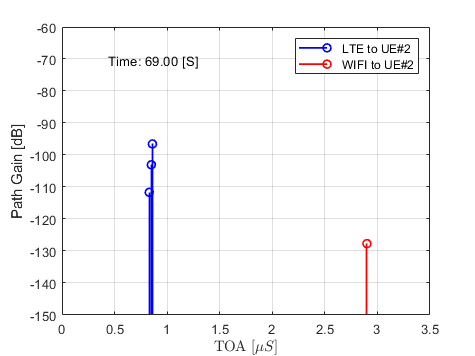

TxID = [1, 2];
RxID = 4;
toa_scale_factor=1e6;
colors = ['b'; 'r';'g';'m'; 'c'; 'k'; 'b'; 'y'];
nPaths = 20;
ffRatio = 16;               % Fast Forward ratio

for snapshotIdx = 1 : size(chMatrix_hat,3)
    figure(5)
    %set(gcf,'Visible','on')    % for external figure for recording
    legends = strings(1,1);
    legendsIdx = 1;
    for TxIdx = 1 : numel(TxID)
        for RxIdx = 1 : numel(RxID)
            Tx = TxID(TxIdx);
            Rx = RxID(RxIdx);

            if size(chMatrix_hat{Tx,Rx,snapshotIdx},1) > 0
                
                    stem(cell2mat(chMatrix_hat{Tx,Rx,snapshotIdx}(:,1))*toa_scale_factor, ...
                        mag2db(abs(cell2mat(chMatrix_hat{Tx,Rx,snapshotIdx}(:,2)))),'BaseValue',(-150), ...
                        'Color',colors((TxIdx-1)*numel(RxID)+RxIdx),'LineWidth',1.25);

                    legends(legendsIdx) = sprintf("%s to %s",parameters.nodes.names{Tx},parameters.nodes.names{Rx});
                    legend(legends);
                    legendsIdx = legendsIdx + 1;
               
            else
                stem([],[]);
            end

            hold on
        end
    end

    hold off
    ylim([-150,-60])
    xlim([0,3.5])
    ylabel('Path Gain [dB]');
    xlabel('TOA [$$\mu S$$]','Interpreter','latex');
    grid on
    text(xlim*[7/8;1/8],ylim*[1/8;7/8]+1,sprintf('Time: %.2f [S]',Time(snapshotIdx)*1e-3));

    pause(parameters.Ts/ffRatio);   
end

## Time evolution of Taps

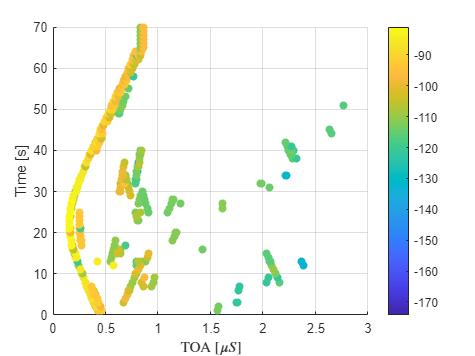

TxID = 1;
RxID = 4;
toa_scale_factor=1e6;

figure(6)
tau =[];
for snapshotIdx = 1:size(chMatrix,3)
    scatter( cell2mat(chMatrix_hat{TxID,RxID,snapshotIdx}(:,1)) * toa_scale_factor, ...
             ones(size(chMatrix_hat{TxID,RxID,snapshotIdx}(:,1))) * parameters.Ts * snapshotIdx, [], ...
             mag2db(abs(cell2mat(chMatrix_hat{TxID,RxID,snapshotIdx}(:,2)))) , 'filled');
    hold on
end
colorbar
grid on
xlabel('TOA [$\mu S$]','Interpreter','latex');
ylabel('Time [s]')